# Modism Project 3 - 1A

## Question

On November 24th, 2021, a spacecraft named DART was launched. Its mission is to fly itself into an asteroid to test out weather such an impact could be a feasible method to redirect an earth-threating object. 

In this model, we are **predicting** weather DART would have been able to redirect the Chicxulub impactors (the asteroid hypothesized to have led to the dinosaur extinction) and if so, how many years in advance would DART need to collide to produce a safe trajectory. 

This is an interesting question because it might demonstrate that humans have power to influence cosmic phenome that would otherwise lead to human extinction. Additionally, it could highlight what areas of research are necessary to make DART be effective against larger asteroids.

## Method

We will begin by developing a 2d model of our system. The earth is placed statically at the origin while the Chicxulub asteroid is free to move around according got Newtonian physics.

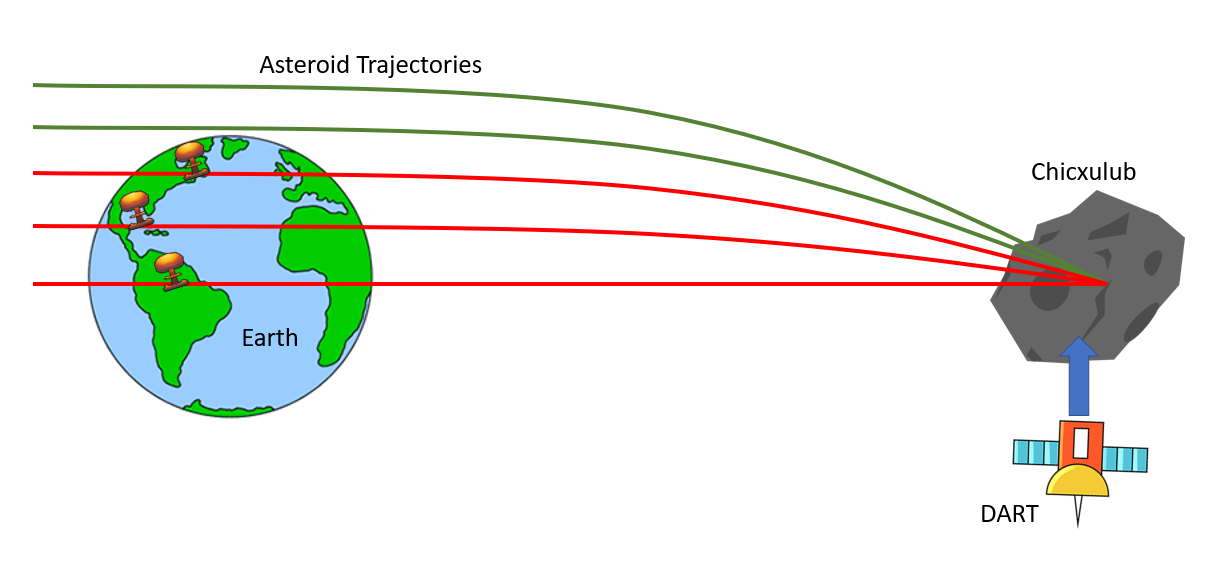

We will use the equation for standard gravitation to determine the motion of the asteroid.


$$\frac{d^2x}{dt^2} = -G\frac{m_{earth}}{x^2}\hat{r}$$


- Where $\hat{r}$ is a unit vector that points from the center of the asteroid to the origin (center of earth).

This system can be decomposed into the following first order system:

- 
$$\frac{dv}{dt} = -G\frac{m_{earth}}{x^2} \hat{r}$$


- 
$$\frac{dx}{dt} = v$$


We will need position and velocity data for the Chicxulub asteroid however this data is not widely available. What we do have access to are the final conditions of the asteroid (position, speed, and impact angle) which means we can run our model “backwards” to simulate what the Chicxulub trajectory might have looked like. We do this by setting the initial conditions of the model to the “final conditions” of the asteroid, remembering to multiply the initial velocity and the gravity equation by -1. Then we run the model “backwards” for as long as we need in order to generate the necessary position and velocity data.

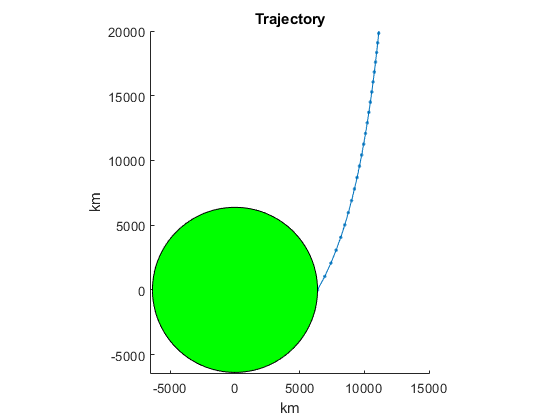

global year2sec
year2sec = 364.25 * 24 * 3600;

years = 0.01 * year2sec;
chic_data = chicxulub(years, 100);  %generate data for the asteriod for 0.01 years at 0.001 hour timesteps
plot_traj(chic_data); %plot the trajectory
axis([-6500 15000 -6500 20000])

max_time = 5*365*24;
dt = 1;
path = chicxulub(max_time, dt); % calculate the trajectory of the impactor

This graph shows the first (or last depending on how you think about it) few datapoints from the reconstructed trajectory.

When the DART spacecraft collides with the asteroid, we will use conservation of momentum to find the new velocity of the asteroid at the time of collision. This momentum transfer is government by the following equations:

- 
$$P_{chic} + P_{DART} = P_{comb}$$


- 
$$m_{chic}v_{chic} + m_{DART}v_{DART} = m_{comb}v_{comb}$$


- 
$$v_{comb} = \frac{m_{chic}v_{chic} + m_{DART}v_{DART}}{m_{comb}}$$


Initial testing revealed that even if the DART impact was a thousand years before earth impact, the trajectory would not be altered significantly. While this might be semi-realistic, there is some error involved with using both very large and very small numbers. The change in angle of the velocity after DART impact is so small that it cannot be correctly computed with ordinary double precision floating point number. For the sake of generating results, we opted to increase the mass of DART from 500kg to 1e11 kg just so that we might see a difference in a more measurable timeframe.

Iteration: In our initial model, we chose an arbitrary trajectory for the Chicxulub impactor where it crashes directly into the Earth. However, we did some research and found the real impact angle and then created a function that calculates a more-realistic trajectory for the impactor. In the first iteration of our model, we parameter-swept the distance from the Earth at which the DART collides with the impactor. In this current interation of our model, we parameter-sweep the time at which the DART collides with the impactor, where the position is determined using the impactor's calculated trajectory

## Results

max_time = 4*year2sec;
dt = 100;
chic_data = chicxulub(max_time, dt); % calculate the trajectory of the impactor

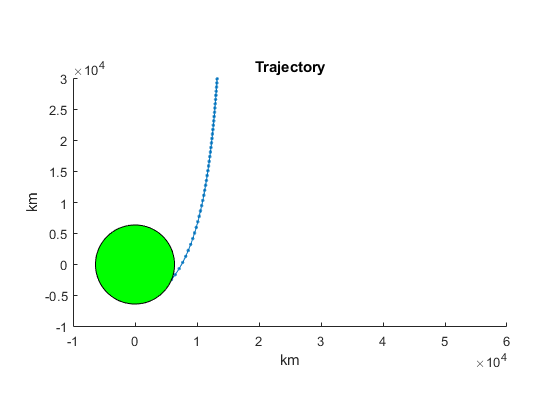


[t, d, i] = trajectory(year2sec * 0.5, dt, chic_data);
plot_traj([t d])


dt = 100;
t_range = year2sec * 0.1 : year2sec * 0.2 : year2sec * 2.1;
impacts = zeros(2, length(t_range));
figure
    clf
    x = linspace(0,2*pi,100);
    y = linspace(0,2*pi,100);
    x = 6378*sin(x);
    y = 6378*cos(y);
    
    
    
    hold on
    patch(x, y, "green")
    

for i=1:length(t_range)
    [t, X, impact] = trajectory(t_range(i), dt, chic_data); % if DART hits at max_time-i, will the impactor impact?
    impacts(1,i) = ~isempty(impact);
    impacts(2,i) = min(vecnorm(X(:,1:2)'));
    if isempty(impact)
        plot(X(:, 1)/1000, X(:, 2)/1000, ".-", "Color", [0.4660 0.6740 0.1880], "LineWidth", 1, "MarkerSize", 8)
    else
        plot(X(:, 1)/1000, X(:, 2)/1000, ".-r", "LineWidth", 1, "MarkerSize", 8)
    end
end

index = int32
31471

da = 1.3620e+12

angle = 0.0014

accel = 	1.0e+-5 *

    0.0002
   -0.2066


accel = 	1.0e+-5 *

    0.0002
   -0.2066


accel = 	1.0e+-5 *

    0.0002
   -0.2066


accel = 	1.0e+-5 *

    0.0002
   -0.2067


accel = 	1.0e+-5 *

    0.0002
   -0.2067


accel = 	1.0e+-5 *

    0.0002
   -0.2067


accel = 	1.0e+-5 *

    0.0002
   -0.2067


accel = 	1.0e+-5 *

    0.0002
   -0.2067


accel = 	1.0e+-5 *

    0.0002
   -0.2067


accel = 	1.0e+-5 *

    0.0002
   -0.2067


accel = 	1.0e+-5 *

    0.0002
   -0.2067


accel = 	1.0e+-5 *

    0.0002
   -0.2067


accel = 	1.0e+-5 *

    0.0002
   -0.2067


accel = 	1.0e+-5 *

    0.0002
   -0.2068


accel = 	1.0e+-5 *

    0.0002
   -0.2068


accel = 	1.0e+-5 *

    0.0002
   -0.2070


accel = 	1.0e+-5 *

    0.0002
   -0.2070


accel = 	1.0e+-5 *

    0.0002
   -0.2070


accel = 	1.0e+-5 *

    0.0002
   -0.2070


accel = 	1.0e+-5 *

    0.0002
   -0.2074


accel = 	1.0e+-5 *

    0.0002
   -0.2075


accel = 	1.0e+-5 *

    0.0002
   -0.2084


accel = 	1.0e+-5 *

    0.0002
   -0.2085


accel = 	1.0e+-5 *

    0.0002
   -0.2087


accel = 	1.0e+-5 *

    0.0002
   -0.2087


accel = 	1.0e+-5 *

    0.0002
   -0.2104


accel = 	1.0e+-5 *

    0.0002
   -0.2112


accel = 	1.0e+-5 *

    0.0002
   -0.2155


accel = 	1.0e+-5 *

    0.0002
   -0.2162


accel = 	1.0e+-5 *

    0.0002
   -0.2172


accel = 	1.0e+-5 *

    0.0002
   -0.2172


accel = 	1.0e+-5 *

    0.0002
   -0.2263


accel = 	1.0e+-5 *

    0.0002
   -0.2310


accel = 	1.0e+-5 *

    0.0003
   -0.2571


accel = 	1.0e+-5 *

    0.0003
   -0.2622


accel = 	1.0e+-5 *

    0.0003
   -0.2688


accel = 	1.0e+-5 *

    0.0003
   -0.2688


accel = 	1.0e+-5 *

    0.0003
   -0.2814


accel = 	1.0e+-5 *

    0.0003
   -0.2881


accel = 	1.0e+-5 *

    0.0003
   -0.3252


accel = 	1.0e+-5 *

    0.0003
   -0.3325


accel = 	1.0e+-5 *

    0.0003
   -0.3421


accel = 	1.0e+-5 *

    0.0003
   -0.3421


accel = 	1.0e+-5 *

    0.0003
   -0.3603


accel = 	1.0e+-5 *

    0.0003
   -0.3700


accel = 	1.0e+-5 *

    0.0003
   -0.4247


accel = 	1.0e+-5 *

    0.0003
   -0.4357


accel = 	1.0e+-5 *

    0.0003
   -0.4500


accel = 	1.0e+-5 *

    0.0003
   -0.4500


accel = 	1.0e+-5 *

    0.0003
   -0.4777


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.4925


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.5780


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.5955


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.6186


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.6186


accel = 2×1
	1.0e+-5 *

    0.0001
   -0.6636


accel = 2×1
	1.0e+-5 *

    0.0001
   -0.6879


accel = 2×1
	1.0e+-5 *

   -0.0000
   -0.8325


accel = 2×1
	1.0e+-5 *

   -0.0000
   -0.8629


accel = 2×1
	1.0e+-5 *

   -0.0001
   -0.9033


accel = 2×1
	1.0e+-5 *

   -0.0001
   -0.9033


accel = 2×1
	1.0e+-5 *

   -0.0002
   -0.9836


accel = 2×1
	1.0e+-4 *

   -0.0000
   -0.1028


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1301


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1361


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1442


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1442


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1607


accel = 2×1
	1.0e+-4 *

   -0.0002
   -0.1701


accel = 2×1
	1.0e+-4 *

   -0.0003
   -0.2317


accel = 2×1
	1.0e+-4 *

   -0.0004
   -0.2461


accel = 2×1
	1.0e+-4 *

   -0.0005
   -0.2661


accel = 2×1
	1.0e+-4 *

   -0.0005
   -0.2661


accel = 2×1
	1.0e+-4 *

   -0.0006
   -0.3088


accel = 2×1
	1.0e+-4 *

   -0.0008
   -0.3341


accel = 2×1
	1.0e+-4 *

   -0.0018
   -0.5237


accel = 2×1
	1.0e+-4 *

   -0.0021
   -0.5742


accel = 2×1
	1.0e+-4 *

   -0.0026
   -0.6480


accel = 2×1
	1.0e+-4 *

   -0.0026
   -0.6478


accel = 2×1
	1.0e+-4 *

   -0.0039
   -0.8219


accel = 2×1
	1.0e+-4 *

   -0.0049
   -0.9369


accel = 2×1
	1.0e+-3 *

   -0.0019
   -0.2144


accel = 2×1
	1.0e+-3 *

   -0.0027
   -0.2601


accel = 2×1
	1.0e+-3 *

   -0.0041
   -0.3406


accel = 2×1
	1.0e+-3 *

   -0.0041
   -0.3398


accel = 2×1
	1.0e+-3 *

   -0.0082
   -0.5284


accel = 2×1
	1.0e+-3 *

   -0.0123
   -0.6895


accel = 2×1
   -0.0006
   -0.0090


accel = 2×1
   -0.0047
   -0.0344


accel = 2×1
   -0.0334
    0.1412


accel = 2×1
   -0.9864
    0.0645


accel = 2×1
	1.0e+-3 *

   -0.0044
   -0.3587


accel = 2×1
	1.0e+-3 *

   -0.0046
   -0.3688


accel = 2×1
	1.0e+-3 *

   -0.0058
   -0.4262


accel = 2×1
	1.0e+-3 *

   -0.0061
   -0.4379


accel = 2×1
	1.0e+-3 *

   -0.0064
   -0.4531


accel = 2×1
	1.0e+-3 *

   -0.0064
   -0.4530


accel = 2×1
	1.0e+-3 *

   -0.0071
   -0.4825


accel = 2×1
	1.0e+-3 *

   -0.0074
   -0.4983


accel = 2×1
	1.0e+-3 *

   -0.0097
   -0.5906


accel = 2×1
	1.0e+-3 *

   -0.0102
   -0.6097


accel = 2×1
	1.0e+-3 *

   -0.0109
   -0.6349


accel = 2×1
	1.0e+-3 *

   -0.0109
   -0.6348


accel = 2×1
	1.0e+-3 *

   -0.0199
   -0.9383


accel = 2×1
   -0.0000
   -0.0012


accel = 2×1
   -0.0005
   -0.0083


accel = 2×1
   -0.0017
   -0.0174


accel = 2×1
   -0.0255
   -0.1092


accel = 2×1
   -0.0177
   -0.0827


accel = 2×1
	1.0e+-3 *

   -0.0127
   -0.7038


accel = 2×1
	1.0e+-3 *

   -0.0139
   -0.7427


accel = 2×1
	1.0e+-3 *

   -0.0218
   -0.9960


accel = 2×1
   -0.0000
   -0.0011


accel = 2×1
   -0.0000
   -0.0011


accel = 2×1
   -0.0000
   -0.0011


accel = 2×1
   -0.0000
   -0.0013


accel = 2×1
   -0.0000
   -0.0014


accel = 2×1
   -0.0001
   -0.0021


accel = 2×1
   -0.0001
   -0.0023


accel = 2×1
   -0.0001
   -0.0026


accel = 2×1
   -0.0001
   -0.0026


accel = 2×1
   -0.0002
   -0.0036


accel = 2×1
   -0.0002
   -0.0044


accel = 2×1
   -0.0017
   -0.0177


accel = 2×1
   -0.0032
   -0.0275


accel = 2×1
   -0.0095
   -0.0570


accel = 2×1
   -0.0087
   -0.0531


accel = 2×1
   -0.0001
   -0.0029


accel = 2×1
   -0.0001
   -0.0031


accel = 2×1
   -0.0002
   -0.0042


accel = 2×1
   -0.0002
   -0.0045


accel = 2×1
   -0.0002
   -0.0049


accel = 2×1
   -0.0002
   -0.0049


accel = 2×1
   -0.0003
   -0.0057


accel = 2×1
   -0.0003
   -0.0062


accel = 2×1
   -0.0007
   -0.0099


accel = 2×1
   -0.0008
   -0.0109


accel = 2×1
   -0.0010
   -0.0124


accel = 2×1
   -0.0010
   -0.0124


accel = 2×1
   -0.0014
   -0.0158


accel = 2×1
   -0.0017
   -0.0181


accel = 2×1
   -0.0067
   -0.0448


accel = 2×1
   -0.0095
   -0.0569


accel = 2×1
   -0.0153
   -0.0789


accel = 2×1
   -0.0148
   -0.0764


accel = 2×1
   -0.0012
   -0.0141


accel = 2×1
   -0.0013
   -0.0150


accel = 2×1
   -0.0023
   -0.0221


accel = 2×1
   -0.0026
   -0.0239


accel = 2×1
   -0.0031
   -0.0265


accel = 2×1
   -0.0031
   -0.0264


accel = 2×1
   -0.0041
   -0.0322


accel = 2×1
   -0.0048
   -0.0359


accel = 2×1
   -0.0131
   -0.0707


accel = 2×1
   -0.0167
   -0.0833


accel = 2×1
   -0.0228
   -0.1030


accel = 2×1
   -0.0223
   -0.1009


accel = 2×1
   -0.0038
   -0.0304


accel = 2×1
   -0.0042
   -0.0328


accel = 2×1
   -0.0080
   -0.0506


accel = 2×1
   -0.0092
   -0.0556


accel = 2×1
   -0.0109
   -0.0625


accel = 2×1
   -0.0109
   -0.0622


accel = 2×1
   -0.0154
   -0.0785


accel = 2×1
   -0.0187
   -0.0896


accel = 2×1
   -0.0682
   -0.2154


accel = 2×1
   -0.0973
   -0.2746


accel = 2×1
   -0.1562
   -0.3766


accel = 2×1
   -0.1466
   -0.3574


accel = 2×1
   -0.0130
   -0.0702


accel = 2×1
   -0.0143
   -0.0749


accel = 2×1
   -0.0246
   -0.1080


accel = 2×1
   -0.0275
   -0.1166


accel = 2×1
   -0.0317
   -0.1284


accel = 2×1
   -0.0315
   -0.1277


accel = 2×1
   -0.0416
   -0.1539


accel = 2×1
   -0.0485
   -0.1708


accel = 2×1
   -0.1261
   -0.3246


accel = 2×1
   -0.1598
   -0.3815


accel = 2×1
   -0.2154
   -0.4641


accel = 2×1
   -0.2082
   -0.4503


accel = 2×1
   -0.0385
   -0.1461


accel = 2×1
   -0.0428
   -0.1571


accel = 2×1
   -0.0793
   -0.2380


accel = 2×1
   -0.0907
   -0.2609


accel = 2×1
   -0.1073
   -0.2919


accel = 2×1
   -0.1063
   -0.2890


accel = 2×1
   -0.1480
   -0.3595


accel = 2×1
   -0.1791
   -0.4079


accel = 2×1
   -0.6341
   -0.9135


accel = 2×1
   -0.9105
   -1.1411


accel = 2×1
   -1.4331
   -1.4637


accel = 2×1
   -1.3024
   -1.3610


accel = 2×1
   -0.1261
   -0.3236


accel = 2×1
   -0.1382
   -0.3440


accel = 2×1
   -0.2313
   -0.4828


accel = 2×1
   -0.2580
   -0.5194


accel = 2×1
   -0.2956
   -0.5667


accel = 2×1
   -0.2931
   -0.5620


accel = 2×1
   -0.3810
   -0.6632


accel = 2×1
   -0.4415
   -0.7280


accel = 2×1
   -1.0851
   -1.2444


accel = 2×1
   -1.3635
   -1.4205


accel = 2×1
   -1.7827
   -1.6191


accel = 2×1
   -1.6969
   -1.5533


accel = 2×1
   -0.3560
   -0.6358


accel = 2×1
   -0.3959
   -0.6801


accel = 2×1
   -0.7260
   -0.9874


accel = 2×1
   -0.8315
   -1.0740


accel = 2×1
   -0.9793
   -1.1781


accel = 2×1
   -0.9628
   -1.1588


accel = 2×1
   -1.3212
   -1.3695


accel = 2×1
   -1.5879
   -1.5035


accel = 2×1
   -4.9338
   -1.9928


accel = 2×1
   -6.7194
   -1.7267


accel = 2×1
   -8.9476
   -0.6695


accel = 2×1
   -7.9345
   -0.8535


accel = 2×1
   -1.1787
   -1.2926


accel = 2×1
   -1.3177
   -1.3718


accel = 2×1
   -2.4761
   -1.8249


accel = 2×1
   -2.8654
   -1.9366


accel = 2×1
   -3.3742
   -2.0107


accel = 2×1
   -3.2778
   -1.9579


accel = 2×1
   -4.4302
   -1.9589


accel = 2×1
   -5.2715
   -1.8695


accel = 2×1
  -11.8535
    3.1885


accel = 2×1
  -13.4969
    6.9491


accel = 2×1
  -12.6858
   10.3425


accel = 2×1
  -11.7595
    8.2891


accel = 2×1
   -4.0026
   -1.9884


accel = 2×1
   -4.4706
   -1.9796


accel = 2×1
   -7.8931
   -1.0003


accel = 2×1
   -9.0170
   -0.4999


accel = 2×1
  -10.0236
    0.4003


accel = 2×1
   -9.5004
    0.3342


accel = 2×1
  -10.9290
    2.5558


accel = 2×1
  -11.6576
    4.1859


accel = 2×1
   -8.6711
   14.3044


accel = 2×1
   -7.0789
   18.4117


accel = 2×1
   -3.7200
   16.9275


accel = 2×1
   -3.9574
   13.5402


accel = 2×1
  -10.5296
    1.6701


accel = 2×1
  -11.0935
    2.5404


accel = 2×1
  -12.0256
    8.4811


accel = 2×1
  -12.2786
   10.1553


accel = 2×1
  -11.2816
   11.4864


accel = 2×1
  -10.4958
   10.6805


index = int32
94414

da = 1.3620e+12

angle = 0.0014

accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2321


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2321


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2321


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2322


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2322


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2322


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2322


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2322


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2322


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2322


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2322


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2322


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2322


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2322


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2322


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2323


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2323


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2323


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2323


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2324


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2325


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2328


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2328


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2329


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2329


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2335


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2338


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2354


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2357


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2360


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2360


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2392


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2408


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2491


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2506


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2526


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2526


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2634


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2691


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.3005


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.3067


accel = 2×1
	1.0e+-6 *

    0.0006
   -0.3146


accel = 2×1
	1.0e+-6 *

    0.0006
   -0.3146


accel = 2×1
	1.0e+-6 *

    0.0006
   -0.3298


accel = 2×1
	1.0e+-6 *

    0.0006
   -0.3378


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.3824


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.3913


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.4028


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.4028


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.4249


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.4366


accel = 2×1
	1.0e+-6 *

    0.0008
   -0.5031


accel = 2×1
	1.0e+-6 *

    0.0008
   -0.5165


accel = 2×1
	1.0e+-6 *

    0.0009
   -0.5340


accel = 2×1
	1.0e+-6 *

    0.0009
   -0.5340


accel = 2×1
	1.0e+-6 *

    0.0009
   -0.5679


accel = 2×1
	1.0e+-6 *

    0.0009
   -0.5860


accel = 2×1
	1.0e+-6 *

    0.0011
   -0.6913


accel = 2×1
	1.0e+-6 *

    0.0011
   -0.7130


accel = 2×1
	1.0e+-6 *

    0.0011
   -0.7416


accel = 2×1
	1.0e+-6 *

    0.0011
   -0.7416


accel = 2×1
	1.0e+-6 *

    0.0012
   -0.7975


accel = 2×1
	1.0e+-6 *

    0.0012
   -0.8278


accel = 2×1
	1.0e+-5 *

    0.0001
   -0.1009


accel = 2×1
	1.0e+-5 *

    0.0001
   -0.1048


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.1099


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.1099


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.1201


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.1257


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.1610


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.1688


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.1793


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.1793


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.2010


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.2134


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.2964


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.3161


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.3437


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.3437


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.4034


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.4392


accel = 2×1
	1.0e+-5 *

    0.0000
   -0.7172


accel = 2×1
	1.0e+-5 *

   -0.0000
   -0.7938


accel = 2×1
	1.0e+-5 *

   -0.0002
   -0.9080


accel = 2×1
	1.0e+-5 *

   -0.0002
   -0.9079


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1186


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1376


accel = 2×1
	1.0e+-4 *

   -0.0010
   -0.3650


accel = 2×1
	1.0e+-4 *

   -0.0015
   -0.4632


accel = 2×1
	1.0e+-4 *

   -0.0028
   -0.6530


accel = 2×1
	1.0e+-4 *

   -0.0028
   -0.6520


accel = 2×1
	1.0e+-3 *

   -0.0006
   -0.1013


accel = 2×1
	1.0e+-3 *

   -0.0009
   -0.1320


accel = 2×1
   -0.0000
   -0.0016


accel = 2×1
   -0.0003
   -0.0052


accel = 2×1
   -0.1424
    0.3021


accel = 2×1
   -1.1006
   -0.4206


accel = 2×1
	1.0e+-4 *

   -0.0031
   -0.6873


accel = 2×1
	1.0e+-4 *

   -0.0032
   -0.7060


accel = 2×1
	1.0e+-4 *

   -0.0041
   -0.8122


accel = 2×1
	1.0e+-4 *

   -0.0043
   -0.8336


accel = 2×1
	1.0e+-4 *

   -0.0045
   -0.8616


accel = 2×1
	1.0e+-4 *

   -0.0045
   -0.8616


accel = 2×1
	1.0e+-4 *

   -0.0050
   -0.9155


accel = 2×1
	1.0e+-4 *

   -0.0053
   -0.9444


accel = 2×1
	1.0e+-3 *

   -0.0007
   -0.1112


accel = 2×1
	1.0e+-3 *

   -0.0007
   -0.1146


accel = 2×1
	1.0e+-3 *

   -0.0008
   -0.1192


accel = 2×1
	1.0e+-3 *

   -0.0008
   -0.1192


accel = 2×1
	1.0e+-3 *

   -0.0015
   -0.1756


accel = 2×1
	1.0e+-3 *

   -0.0021
   -0.2204


accel = 2×1
   -0.0000
   -0.0014


accel = 2×1
   -0.0001
   -0.0028


accel = 2×1
   -0.0009
   -0.0113


accel = 2×1
   -0.0008
   -0.0104


accel = 2×1
	1.0e+-3 *

   -0.0009
   -0.1323


accel = 2×1
	1.0e+-3 *

   -0.0010
   -0.1398


accel = 2×1
	1.0e+-3 *

   -0.0017
   -0.1884


accel = 2×1
	1.0e+-3 *

   -0.0018
   -0.1997


accel = 2×1
	1.0e+-3 *

   -0.0021
   -0.2152


accel = 2×1
	1.0e+-3 *

   -0.0021
   -0.2152


accel = 2×1
	1.0e+-3 *

   -0.0026
   -0.2482


accel = 2×1
	1.0e+-3 *

   -0.0029
   -0.2677


accel = 2×1
	1.0e+-3 *

   -0.0058
   -0.4110


accel = 2×1
	1.0e+-3 *

   -0.0066
   -0.4486


accel = 2×1
	1.0e+-3 *

   -0.0079
   -0.5030


accel = 2×1
	1.0e+-3 *

   -0.0079
   -0.5026


accel = 2×1
	1.0e+-3 *

   -0.0157
   -0.7822


accel = 2×1
   -0.0000
   -0.0010


accel = 2×1
   -0.0012
   -0.0139


accel = 2×1
   -0.0104
   -0.0563


accel = 2×1
   -0.0254
    0.1215


accel = 2×1
   -0.7141
   -0.0131


accel = 2×1
	1.0e+-3 *

   -0.0085
   -0.5248


accel = 2×1
	1.0e+-3 *

   -0.0088
   -0.5364


accel = 2×1
	1.0e+-3 *

   -0.0104
   -0.6009


accel = 2×1
	1.0e+-3 *

   -0.0108
   -0.6136


accel = 2×1
	1.0e+-3 *

   -0.0112
   -0.6301


accel = 2×1
	1.0e+-3 *

   -0.0112
   -0.6300


accel = 2×1
	1.0e+-3 *

   -0.0121
   -0.6614


accel = 2×1
	1.0e+-3 *

   -0.0126
   -0.6779


accel = 2×1
	1.0e+-3 *

   -0.0154
   -0.7709


accel = 2×1
	1.0e+-3 *

   -0.0160
   -0.7894


accel = 2×1
	1.0e+-3 *

   -0.0167
   -0.8136


accel = 2×1
	1.0e+-3 *

   -0.0167
   -0.8135


accel = 2×1
   -0.0000
   -0.0011


accel = 2×1
   -0.0000
   -0.0013


accel = 2×1
   -0.0002
   -0.0041


accel = 2×1
   -0.0003
   -0.0056


accel = 2×1
   -0.0006
   -0.0089


accel = 2×1
   -0.0006
   -0.0088


accel = 2×1
	1.0e+-3 *

   -0.0200
   -0.9126


accel = 2×1
	1.0e+-3 *

   -0.0219
   -0.9693


accel = 2×1
   -0.0000
   -0.0014


accel = 2×1
   -0.0000
   -0.0014


accel = 2×1
   -0.0000
   -0.0016


accel = 2×1
   -0.0000
   -0.0016


accel = 2×1
   -0.0001
   -0.0019


accel = 2×1
   -0.0001
   -0.0020


accel = 2×1
   -0.0001
   -0.0034


accel = 2×1
   -0.0002
   -0.0037


accel = 2×1
   -0.0002
   -0.0043


accel = 2×1
   -0.0002
   -0.0043


accel = 2×1
   -0.0003
   -0.0058


accel = 2×1
   -0.0004
   -0.0069


accel = 2×1
   -0.0027
   -0.0234


accel = 2×1
   -0.0045
   -0.0335


accel = 2×1
   -0.0102
   -0.0581


accel = 2×1
   -0.0096
   -0.0551


accel = 2×1
   -0.0003
   -0.0048


accel = 2×1
   -0.0003
   -0.0051


accel = 2×1
   -0.0005
   -0.0072


accel = 2×1
   -0.0005
   -0.0077


accel = 2×1
   -0.0006
   -0.0084


accel = 2×1
   -0.0006
   -0.0083


accel = 2×1
   -0.0007
   -0.0098


accel = 2×1
   -0.0008
   -0.0107


accel = 2×1
   -0.0018
   -0.0181


accel = 2×1
   -0.0022
   -0.0203


accel = 2×1
   -0.0027
   -0.0236


accel = 2×1
   -0.0027
   -0.0234


accel = 2×1
   -0.0040
   -0.0308


accel = 2×1
   -0.0051
   -0.0361


accel = 2×1
   -0.0262
   -0.1094


accel = 2×1
   -0.0424
   -0.1521


accel = 2×1
   -0.0857
   -0.2444


accel = 2×1
   -0.0781
   -0.2270


accel = 2×1
   -0.0032
   -0.0262


accel = 2×1
   -0.0035
   -0.0278


accel = 2×1
   -0.0056
   -0.0388


accel = 2×1
   -0.0062
   -0.0415


accel = 2×1
   -0.0071
   -0.0452


accel = 2×1
   -0.0071
   -0.0451


accel = 2×1
   -0.0090
   -0.0531


accel = 2×1
   -0.0103
   -0.0581


accel = 2×1
   -0.0226
   -0.0990


accel = 2×1
   -0.0269
   -0.1118


accel = 2×1
   -0.0338
   -0.1303


accel = 2×1
   -0.0334
   -0.1286


accel = 2×1
   -0.0507
   -0.1702


accel = 2×1
   -0.0648
   -0.2009


accel = 2×1
   -0.4029
   -0.6618


accel = 2×1
   -0.7429
   -0.9566


accel = 2×1
   -1.8493
   -1.5480


accel = 2×1
   -1.4718
   -1.3321


accel = 2×1
   -0.0385
   -0.1417


accel = 2×1
   -0.0416
   -0.1491


accel = 2×1
   -0.0630
   -0.1974


accel = 2×1
   -0.0686
   -0.2090


accel = 2×1
   -0.0762
   -0.2244


accel = 2×1
   -0.0760
   -0.2236


accel = 2×1
   -0.0930
   -0.2556


accel = 2×1
   -0.1037
   -0.2750


accel = 2×1
   -0.1950
   -0.4170


accel = 2×1
   -0.2242
   -0.4580


accel = 2×1
   -0.2666
   -0.5117


accel = 2×1
   -0.2631
   -0.5051


accel = 2×1
   -0.3831
   -0.6390


accel = 2×1
   -0.4783
   -0.7335


accel = 2×1
   -2.2068
   -1.6268


accel = 2×1
   -3.5080
   -1.8232


accel = 2×1
   -6.0198
   -1.4863


accel = 2×1
   -5.0504
   -1.5094


accel = 2×1
   -0.3101
   -0.5606


accel = 2×1
   -0.3388
   -0.5930


accel = 2×1
   -0.5545
   -0.8043


accel = 2×1
   -0.6156
   -0.8585


accel = 2×1
   -0.6995
   -0.9250


accel = 2×1
   -0.6930
   -0.9162


accel = 2×1
   -0.8846
   -1.0507


accel = 2×1
   -1.0143
   -1.1333


accel = 2×1
   -2.2643
   -1.6427


accel = 2×1
   -2.7629
   -1.7736


accel = 2×1
   -3.4326
   -1.8346


accel = 2×1
   -3.2652
   -1.7639


accel = 2×1
   -4.5506
   -1.6436


accel = 2×1
   -5.5138
   -1.4187


accel = 2×1
  -10.9117
    6.6202


accel = 2×1
   -9.7589
   11.1220


accel = 2×1
   -7.0730
   12.5827


accel = 2×1
   -7.8314
   10.8440


accel = 2×1
   -3.9301
   -1.7465


accel = 2×1
   -4.3508
   -1.7102


accel = 2×1
   -7.2421
   -0.6862


accel = 2×1
   -8.1347
   -0.2371


accel = 2×1
   -8.9120
    0.5294


accel = 2×1
   -8.5049
    0.4801


accel = 2×1
   -9.5961
    2.2883


accel = 2×1
  -10.1471
    3.5535


accel = 2×1
   -8.4062
   11.2796


accel = 2×1
   -7.8161
   14.1466


accel = 2×1
   -5.2796
   13.9394


accel = 2×1
   -4.8461
   11.5454


accel = 2×1
   -9.4152
    1.8306


accel = 2×1
   -9.8998
    2.7166


accel = 2×1
  -10.0661
    8.4783


accel = 2×1
  -10.1519
   10.1546


accel = 2×1
   -8.8859
   11.1552


accel = 2×1
   -8.1398
   10.1556


index = int32
157356

da = 1.3620e+12

angle = 0.0014

accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8379


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8379


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8379


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8379


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8379


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8379


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8379


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8379


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8379


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8379


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8380


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8380


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8380


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8380


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8380


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8382


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8382


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8382


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8382


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8385


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8386


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8393


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8394


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8396


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8396


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8409


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8416


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8449


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8455


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8463


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8463


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8530


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8565


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8739


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8770


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8810


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8810


accel = 2×1
	1.0e+-7 *

    0.0018
   -0.9179


accel = 2×1
	1.0e+-7 *

    0.0018
   -0.9373


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1044


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1065


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1092


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1092


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1143


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1170


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1322


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1352


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1391


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1391


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1465


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1504


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1728


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1773


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1831


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1831


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.1945


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2005


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2355


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2427


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2521


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2521


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2705


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2805


accel = 2×1
	1.0e+-6 *

    0.0006
   -0.3398


accel = 2×1
	1.0e+-6 *

    0.0006
   -0.3523


accel = 2×1
	1.0e+-6 *

    0.0006
   -0.3689


accel = 2×1
	1.0e+-6 *

    0.0006
   -0.3689


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.4018


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.4200


accel = 2×1
	1.0e+-6 *

    0.0009
   -0.5325


accel = 2×1
	1.0e+-6 *

    0.0009
   -0.5571


accel = 2×1
	1.0e+-6 *

    0.0009
   -0.5904


accel = 2×1
	1.0e+-6 *

    0.0009
   -0.5904


accel = 2×1
	1.0e+-6 *

    0.0010
   -0.6584


accel = 2×1
	1.0e+-6 *

    0.0011
   -0.6969


accel = 2×1
	1.0e+-6 *

    0.0013
   -0.9514


accel = 2×1
	1.0e+-5 *

    0.0001
   -0.1011


accel = 2×1
	1.0e+-5 *

    0.0001
   -0.1094


accel = 2×1
	1.0e+-5 *

    0.0001
   -0.1094


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.1271


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.1376


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.2163


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.2373


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.2680


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.2680


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.3407


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.3887


accel = 2×1
	1.0e+-5 *

   -0.0003
   -0.8949


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1086


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1424


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1423


accel = 2×1
	1.0e+-4 *

   -0.0004
   -0.2215


accel = 2×1
	1.0e+-4 *

   -0.0007
   -0.2886


accel = 2×1
	1.0e+-3 *

   -0.0046
   -0.3440


accel = 2×1
   -0.0000
   -0.0011


accel = 2×1
   -0.4814
    0.5196


accel = 2×1
   -0.4016
   -0.4466


accel = 2×1
	1.0e+-4 *

   -0.0002
   -0.1481


accel = 2×1
	1.0e+-4 *

   -0.0002
   -0.1512


accel = 2×1
	1.0e+-4 *

   -0.0002
   -0.1679


accel = 2×1
	1.0e+-4 *

   -0.0002
   -0.1712


accel = 2×1
	1.0e+-4 *

   -0.0002
   -0.1754


accel = 2×1
	1.0e+-4 *

   -0.0002
   -0.1754


accel = 2×1
	1.0e+-4 *

   -0.0003
   -0.1834


accel = 2×1
	1.0e+-4 *

   -0.0003
   -0.1876


accel = 2×1
	1.0e+-4 *

   -0.0003
   -0.2109


accel = 2×1
	1.0e+-4 *

   -0.0004
   -0.2156


accel = 2×1
	1.0e+-4 *

   -0.0004
   -0.2215


accel = 2×1
	1.0e+-4 *

   -0.0004
   -0.2215


accel = 2×1
	1.0e+-4 *

   -0.0007
   -0.2886


accel = 2×1
	1.0e+-4 *

   -0.0009
   -0.3343


accel = 2×1
	1.0e+-4 *

   -0.0049
   -0.8744


accel = 2×1
	1.0e+-3 *

   -0.0007
   -0.1105


accel = 2×1
	1.0e+-3 *

   -0.0013
   -0.1547


accel = 2×1
	1.0e+-3 *

   -0.0013
   -0.1544


accel = 2×1
	1.0e+-3 *

   -0.0026
   -0.2399


accel = 2×1
	1.0e+-3 *

   -0.0039
   -0.3126


accel = 2×1
   -0.0002
   -0.0039


accel = 2×1
   -0.0013
   -0.0135


accel = 2×1
   -0.0672
    0.1939


accel = 2×1
   -1.1037
   -0.0039


accel = 2×1
	1.0e+-3 *

   -0.0014
   -0.1648


accel = 2×1
	1.0e+-3 *

   -0.0015
   -0.1704


accel = 2×1
	1.0e+-3 *

   -0.0020
   -0.2032


accel = 2×1
	1.0e+-3 *

   -0.0021
   -0.2101


accel = 2×1
	1.0e+-3 *

   -0.0022
   -0.2191


accel = 2×1
	1.0e+-3 *

   -0.0022
   -0.2191


accel = 2×1
	1.0e+-3 *

   -0.0025
   -0.2369


accel = 2×1
	1.0e+-3 *

   -0.0027
   -0.2466


accel = 2×1
	1.0e+-3 *

   -0.0038
   -0.3057


accel = 2×1
	1.0e+-3 *

   -0.0040
   -0.3184


accel = 2×1
	1.0e+-3 *

   -0.0044
   -0.3355


accel = 2×1
	1.0e+-3 *

   -0.0044
   -0.3355


accel = 2×1
	1.0e+-3 *

   -0.0088
   -0.5217


accel = 2×1
	1.0e+-3 *

   -0.0133
   -0.6808


accel = 2×1
   -0.0007
   -0.0089


accel = 2×1
   -0.0050
   -0.0338


accel = 2×1
   -0.0354
    0.1384


accel = 2×1
   -0.8396
    0.0655


accel = 2×1
	1.0e+-3 *

   -0.0048
   -0.3551


accel = 2×1
	1.0e+-3 *

   -0.0050
   -0.3656


accel = 2×1
	1.0e+-3 *

   -0.0064
   -0.4257


accel = 2×1
	1.0e+-3 *

   -0.0067
   -0.4380


accel = 2×1
	1.0e+-3 *

   -0.0071
   -0.4540


accel = 2×1
	1.0e+-3 *

   -0.0071
   -0.4540


accel = 2×1
	1.0e+-3 *

   -0.0078
   -0.4853


accel = 2×1
	1.0e+-3 *

   -0.0083
   -0.5021


accel = 2×1
	1.0e+-3 *

   -0.0109
   -0.6014


accel = 2×1
	1.0e+-3 *

   -0.0115
   -0.6221


accel = 2×1
	1.0e+-3 *

   -0.0123
   -0.6496


accel = 2×1
	1.0e+-3 *

   -0.0123
   -0.6495


accel = 2×1
	1.0e+-3 *

   -0.0223
   -0.9530


accel = 2×1
   -0.0000
   -0.0012


accel = 2×1
   -0.0005
   -0.0078


accel = 2×1
   -0.0015
   -0.0154


accel = 2×1
   -0.0153
   -0.0733


accel = 2×1
   -0.0119
   -0.0602


accel = 2×1
	1.0e+-3 *

   -0.0145
   -0.7208


accel = 2×1
	1.0e+-3 *

   -0.0158
   -0.7611


accel = 2×1
   -0.0000
   -0.0010


accel = 2×1
   -0.0000
   -0.0011


accel = 2×1
   -0.0000
   -0.0012


accel = 2×1
   -0.0000
   -0.0012


accel = 2×1
   -0.0000
   -0.0013


accel = 2×1
   -0.0000
   -0.0015


accel = 2×1
   -0.0001
   -0.0022


accel = 2×1
   -0.0001
   -0.0024


accel = 2×1
   -0.0001
   -0.0027


accel = 2×1
   -0.0001
   -0.0027


accel = 2×1
   -0.0002
   -0.0037


accel = 2×1
   -0.0002
   -0.0045


accel = 2×1
   -0.0017
   -0.0170


accel = 2×1
   -0.0031
   -0.0254


accel = 2×1
   -0.0082
   -0.0485


accel = 2×1
   -0.0076
   -0.0457


accel = 2×1
   -0.0001
   -0.0031


accel = 2×1
   -0.0001
   -0.0032


accel = 2×1
   -0.0002
   -0.0045


accel = 2×1
   -0.0003
   -0.0048


accel = 2×1
   -0.0003
   -0.0052


accel = 2×1
   -0.0003
   -0.0052


accel = 2×1
   -0.0004
   -0.0061


accel = 2×1
   -0.0004
   -0.0066


accel = 2×1
   -0.0009
   -0.0108


accel = 2×1
   -0.0010
   -0.0120


accel = 2×1
   -0.0013
   -0.0138


accel = 2×1
   -0.0013
   -0.0137


accel = 2×1
   -0.0018
   -0.0177


accel = 2×1
   -0.0023
   -0.0204


accel = 2×1
   -0.0097
   -0.0544


accel = 2×1
   -0.0144
   -0.0711


accel = 2×1
   -0.0249
   -0.1031


accel = 2×1
   -0.0236
   -0.0989


accel = 2×1
   -0.0015
   -0.0155


accel = 2×1
   -0.0017
   -0.0165


accel = 2×1
   -0.0029
   -0.0239


accel = 2×1
   -0.0032
   -0.0258


accel = 2×1
   -0.0037
   -0.0284


accel = 2×1
   -0.0037
   -0.0283


accel = 2×1
   -0.0049
   -0.0341


accel = 2×1
   -0.0057
   -0.0378


accel = 2×1
   -0.0143
   -0.0708


accel = 2×1
   -0.0178
   -0.0822


accel = 2×1
   -0.0236
   -0.0993


accel = 2×1
   -0.0232
   -0.0977


accel = 2×1
   -0.0046
   -0.0327


accel = 2×1
   -0.0051
   -0.0353


accel = 2×1
   -0.0100
   -0.0553


accel = 2×1
   -0.0115
   -0.0610


accel = 2×1
   -0.0138
   -0.0689


accel = 2×1
   -0.0137
   -0.0685


accel = 2×1
   -0.0196
   -0.0872


accel = 2×1
   -0.0241
   -0.1003


accel = 2×1
   -0.0966
   -0.2548


accel = 2×1
   -0.1432
   -0.3321


accel = 2×1
   -0.2434
   -0.4692


accel = 2×1
   -0.2246
   -0.4397


accel = 2×1
   -0.0163
   -0.0769


accel = 2×1
   -0.0178
   -0.0819


accel = 2×1
   -0.0299
   -0.1161


accel = 2×1
   -0.0333
   -0.1249


accel = 2×1
   -0.0381
   -0.1368


accel = 2×1
   -0.0379
   -0.1361


accel = 2×1
   -0.0493
   -0.1621


accel = 2×1
   -0.0570
   -0.1787


accel = 2×1
   -0.1376
   -0.3215


accel = 2×1
   -0.1702
   -0.3711


accel = 2×1
   -0.2222
   -0.4406


accel = 2×1
   -0.2159
   -0.4295


accel = 2×1
   -0.0466
   -0.1561


accel = 2×1
   -0.0520
   -0.1682


accel = 2×1
   -0.0987
   -0.2580


accel = 2×1
   -0.1135
   -0.2838


accel = 2×1
   -0.1354
   -0.3185


accel = 2×1
   -0.1338
   -0.3149


accel = 2×1
   -0.1893
   -0.3940


accel = 2×1
   -0.2314
   -0.4487


accel = 2×1
   -0.8887
   -1.0116


accel = 2×1
   -1.3174
   -1.2514


accel = 2×1
   -2.1353
   -1.5326


accel = 2×1
   -1.8966
   -1.4173


accel = 2×1
   -0.1584
   -0.3515


accel = 2×1
   -0.1735
   -0.3729


accel = 2×1
   -0.2880
   -0.5165


accel = 2×1
   -0.3206
   -0.5538


accel = 2×1
   -0.3661
   -0.6013


accel = 2×1
   -0.3630
   -0.5961


accel = 2×1
   -0.4683
   -0.6955


accel = 2×1
   -0.5401
   -0.7581


accel = 2×1
   -1.2695
   -1.2123


accel = 2×1
   -1.5712
   -1.3527


accel = 2×1
   -2.0042
   -1.4852


accel = 2×1
   -1.9107
   -1.4277


accel = 2×1
   -0.4436
   -0.6735


accel = 2×1
   -0.4950
   -0.7199


accel = 2×1
   -0.9258
   -1.0309


accel = 2×1
   -1.0666
   -1.1172


accel = 2×1
   -1.2610
   -1.2128


accel = 2×1
   -1.2352
   -1.1891


accel = 2×1
   -1.7008
   -1.3610


accel = 2×1
   -2.0477
   -1.4576


accel = 2×1
   -5.9620
   -0.9165


accel = 2×1
   -7.7579
    0.1113


accel = 2×1
   -9.2244
    2.0298


accel = 2×1
   -8.2215
    1.4111


accel = 2×1
   -1.5420
   -1.3115


accel = 2×1
   -1.7443
   -1.3804


accel = 2×1
   -3.4690
   -1.5905


accel = 2×1
   -4.0876
   -1.5824


accel = 2×1
   -4.8188
   -1.4166


accel = 2×1
   -4.5985
   -1.3714


accel = 2×1
   -6.0494
   -0.6703


accel = 2×1
   -7.0252
    0.0138


accel = 2×1
   -8.4429
    9.0692


accel = 2×1
   -6.3661
   12.6219


accel = 2×1
   -3.7028
   11.8588


accel = 2×1
   -4.5511
   10.0494


accel = 2×1
   -5.4055
   -1.0636


accel = 2×1
   -5.8979
   -0.8340


accel = 2×1
   -8.5311
    1.6610


accel = 2×1
   -9.2585
    2.5227


accel = 2×1
   -9.5089
    3.6246


accel = 2×1
   -8.9969
    3.3970


accel = 2×1
   -8.8733
    5.4114


accel = 2×1
   -8.6691
    6.5884


accel = 2×1
   -4.6279
   10.4978


accel = 2×1
   -4.1708
   11.8391


accel = 2×1
   -2.5447
   11.3275


accel = 2×1
   -2.0984
    9.7307


index = int32
220298

da = 1.3620e+12

angle = 0.0014

accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4280


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4280


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4280


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4280


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4280


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4280


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4280


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4280


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4280


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4280


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4280


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4280


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4280


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4280


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4281


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4281


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4281


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4281


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4281


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4282


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4283


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4285


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4286


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4286


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4286


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4291


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4293


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4306


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4308


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4310


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4310


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4335


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4347


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4410


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4422


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4436


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4436


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4566


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4634


accel = 2×1
	1.0e+-7 *

    0.0010
   -0.4995


accel = 2×1
	1.0e+-7 *

    0.0010
   -0.5064


accel = 2×1
	1.0e+-7 *

    0.0010
   -0.5152


accel = 2×1
	1.0e+-7 *

    0.0010
   -0.5152


accel = 2×1
	1.0e+-7 *

    0.0011
   -0.5385


accel = 2×1
	1.0e+-7 *

    0.0011
   -0.5508


accel = 2×1
	1.0e+-7 *

    0.0012
   -0.6190


accel = 2×1
	1.0e+-7 *

    0.0013
   -0.6324


accel = 2×1
	1.0e+-7 *

    0.0013
   -0.6498


accel = 2×1
	1.0e+-7 *

    0.0013
   -0.6498


accel = 2×1
	1.0e+-7 *

    0.0014
   -0.6830


accel = 2×1
	1.0e+-7 *

    0.0014
   -0.7006


accel = 2×1
	1.0e+-7 *

    0.0016
   -0.7995


accel = 2×1
	1.0e+-7 *

    0.0016
   -0.8193


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8450


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8450


accel = 2×1
	1.0e+-7 *

    0.0018
   -0.8946


accel = 2×1
	1.0e+-7 *

    0.0018
   -0.9210


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1072


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1103


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1144


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1144


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1222


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1264


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1513


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1565


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1634


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1634


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1769


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1843


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2294


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2392


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2522


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2522


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2786


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2934


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.3883


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.4100


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.4397


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.4397


accel = 2×1
	1.0e+-6 *

    0.0008
   -0.5019


accel = 2×1
	1.0e+-6 *

    0.0009
   -0.5381


accel = 2×1
	1.0e+-6 *

    0.0011
   -0.7949


accel = 2×1
	1.0e+-6 *

    0.0012
   -0.8595


accel = 2×1
	1.0e+-6 *

    0.0013
   -0.9519


accel = 2×1
	1.0e+-6 *

    0.0013
   -0.9518


accel = 2×1
	1.0e+-5 *

    0.0001
   -0.1160


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.1291


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.2455


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.2822


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.3410


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.3409


accel = 2×1
	1.0e+-5 *

    0.0001
   -0.5054


accel = 2×1
	1.0e+-5 *

    0.0000
   -0.6363


accel = 2×1
	1.0e+-4 *

   -0.0015
   -0.4214


accel = 2×1
	1.0e+-4 *

   -0.0046
   -0.8155


accel = 2×1
	1.0e+-3 *

   -0.0042
   -0.3155


accel = 2×1
	1.0e+-3 *

   -0.0041
   -0.3109


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.4086


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.4502


accel = 2×1
	1.0e+-5 *

   -0.0002
   -0.7976


accel = 2×1
	1.0e+-5 *

   -0.0004
   -0.9006


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1060


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1060


accel = 2×1
	1.0e+-4 *

   -0.0002
   -0.1476


accel = 2×1
	1.0e+-4 *

   -0.0003
   -0.1783


accel = 2×1
	1.0e+-4 *

   -0.0036
   -0.7044


accel = 2×1
	1.0e+-3 *

   -0.0007
   -0.1039


accel = 2×1
	1.0e+-3 *

   -0.0019
   -0.1942


accel = 2×1
	1.0e+-3 *

   -0.0019
   -0.1933


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1363


accel = 2×1
	1.0e+-4 *

   -0.0002
   -0.1566


accel = 2×1
	1.0e+-4 *

   -0.0012
   -0.3825


accel = 2×1
	1.0e+-4 *

   -0.0018
   -0.4727


accel = 2×1
	1.0e+-4 *

   -0.0030
   -0.6382


accel = 2×1
	1.0e+-4 *

   -0.0030
   -0.6374


accel = 2×1
	1.0e+-4 *

   -0.0064
   -0.9906


accel = 2×1
	1.0e+-3 *

   -0.0010
   -0.1290


accel = 2×1
   -0.0000
   -0.0016


accel = 2×1
   -0.0003
   -0.0051


accel = 2×1
   -0.1399
    0.2802


accel = 2×1
   -0.9914
   -0.3231


accel = 2×1
	1.0e+-4 *

   -0.0033
   -0.6724


accel = 2×1
	1.0e+-4 *

   -0.0035
   -0.6910


accel = 2×1
	1.0e+-4 *

   -0.0044
   -0.7968


accel = 2×1
	1.0e+-4 *

   -0.0046
   -0.8181


accel = 2×1
	1.0e+-4 *

   -0.0049
   -0.8460


accel = 2×1
	1.0e+-4 *

   -0.0049
   -0.8460


accel = 2×1
	1.0e+-4 *

   -0.0054
   -0.9000


accel = 2×1
	1.0e+-4 *

   -0.0057
   -0.9289


accel = 2×1
	1.0e+-3 *

   -0.0008
   -0.1097


accel = 2×1
	1.0e+-3 *

   -0.0008
   -0.1132


accel = 2×1
	1.0e+-3 *

   -0.0009
   -0.1177


accel = 2×1
	1.0e+-3 *

   -0.0009
   -0.1177


accel = 2×1
	1.0e+-3 *

   -0.0017
   -0.1829


accel = 2×1
	1.0e+-3 *

   -0.0027
   -0.2383


accel = 2×1
   -0.0001
   -0.0029


accel = 2×1
   -0.0008
   -0.0099


accel = 2×1
   -0.0869
    0.2170


accel = 2×1
   -1.0620
   -0.0946


accel = 2×1
	1.0e+-3 *

   -0.0010
   -0.1259


accel = 2×1
	1.0e+-3 *

   -0.0010
   -0.1303


accel = 2×1
	1.0e+-3 *

   -0.0014
   -0.1564


accel = 2×1
	1.0e+-3 *

   -0.0014
   -0.1618


accel = 2×1
	1.0e+-3 *

   -0.0015
   -0.1690


accel = 2×1
	1.0e+-3 *

   -0.0015
   -0.1690


accel = 2×1
	1.0e+-3 *

   -0.0018
   -0.1833


accel = 2×1
	1.0e+-3 *

   -0.0019
   -0.1911


accel = 2×1
	1.0e+-3 *

   -0.0027
   -0.2390


accel = 2×1
	1.0e+-3 *

   -0.0029
   -0.2494


accel = 2×1
	1.0e+-3 *

   -0.0031
   -0.2633


accel = 2×1
	1.0e+-3 *

   -0.0031
   -0.2633


accel = 2×1
	1.0e+-3 *

   -0.0063
   -0.4093


accel = 2×1
	1.0e+-3 *

   -0.0095
   -0.5337


accel = 2×1
   -0.0005
   -0.0068


accel = 2×1
   -0.0033
   -0.0250


accel = 2×1
   -0.0459
    0.1547


accel = 2×1
   -0.8722
    0.0684


accel = 2×1
	1.0e+-3 *

   -0.0034
   -0.2800


accel = 2×1
	1.0e+-3 *

   -0.0036
   -0.2890


accel = 2×1
	1.0e+-3 *

   -0.0047
   -0.3413


accel = 2×1
	1.0e+-3 *

   -0.0049
   -0.3521


accel = 2×1
	1.0e+-3 *

   -0.0053
   -0.3663


accel = 2×1
	1.0e+-3 *

   -0.0053
   -0.3663


accel = 2×1
	1.0e+-3 *

   -0.0059
   -0.3941


accel = 2×1
	1.0e+-3 *

   -0.0063
   -0.4092


accel = 2×1
	1.0e+-3 *

   -0.0086
   -0.4999


accel = 2×1
	1.0e+-3 *

   -0.0091
   -0.5192


accel = 2×1
	1.0e+-3 *

   -0.0098
   -0.5449


accel = 2×1
	1.0e+-3 *

   -0.0098
   -0.5448


accel = 2×1
	1.0e+-3 *

   -0.0195
   -0.8485


accel = 2×1
   -0.0000
   -0.0011


accel = 2×1
   -0.0016
   -0.0153


accel = 2×1
   -0.0135
   -0.0634


accel = 2×1
   -0.0235
    0.1115


accel = 2×1
   -0.5556
   -0.0132


accel = 2×1
	1.0e+-3 *

   -0.0104
   -0.5671


accel = 2×1
	1.0e+-3 *

   -0.0108
   -0.5788


accel = 2×1
	1.0e+-3 *

   -0.0127
   -0.6431


accel = 2×1
	1.0e+-3 *

   -0.0131
   -0.6556


accel = 2×1
	1.0e+-3 *

   -0.0136
   -0.6718


accel = 2×1
	1.0e+-3 *

   -0.0136
   -0.6718


accel = 2×1
	1.0e+-3 *

   -0.0145
   -0.7026


accel = 2×1
	1.0e+-3 *

   -0.0151
   -0.7187


accel = 2×1
	1.0e+-3 *

   -0.0181
   -0.8088


accel = 2×1
	1.0e+-3 *

   -0.0187
   -0.8266


accel = 2×1
	1.0e+-3 *

   -0.0195
   -0.8496


accel = 2×1
	1.0e+-3 *

   -0.0195
   -0.8496


accel = 2×1
   -0.0000
   -0.0011


accel = 2×1
   -0.0000
   -0.0013


accel = 2×1
   -0.0002
   -0.0035


accel = 2×1
   -0.0002
   -0.0045


accel = 2×1
   -0.0004
   -0.0064


accel = 2×1
   -0.0004
   -0.0063


accel = 2×1
	1.0e+-3 *

   -0.0238
   -0.9671


accel = 2×1
   -0.0000
   -0.0010


accel = 2×1
   -0.0000
   -0.0015


accel = 2×1
   -0.0001
   -0.0016


accel = 2×1
   -0.0001
   -0.0018


accel = 2×1
   -0.0001
   -0.0018


accel = 2×1
   -0.0001
   -0.0022


accel = 2×1
   -0.0001
   -0.0024


accel = 2×1
   -0.0003
   -0.0046


accel = 2×1
   -0.0003
   -0.0054


accel = 2×1
   -0.0004
   -0.0065


accel = 2×1
   -0.0004
   -0.0064


accel = 2×1
   -0.0001
   -0.0021


accel = 2×1
   -0.0001
   -0.0023


accel = 2×1
   -0.0002
   -0.0035


accel = 2×1
   -0.0002
   -0.0038


accel = 2×1
   -0.0002
   -0.0043


accel = 2×1
   -0.0002
   -0.0042


accel = 2×1
   -0.0003
   -0.0053


accel = 2×1
   -0.0004
   -0.0060


accel = 2×1
   -0.0013
   -0.0134


accel = 2×1
   -0.0017
   -0.0163


accel = 2×1
   -0.0025
   -0.0212


accel = 2×1
   -0.0024
   -0.0209


accel = 2×1
   -0.0003
   -0.0049


accel = 2×1
   -0.0003
   -0.0052


accel = 2×1
   -0.0006
   -0.0078


accel = 2×1
   -0.0006
   -0.0085


accel = 2×1
   -0.0008
   -0.0095


accel = 2×1
   -0.0007
   -0.0094


accel = 2×1
   -0.0010
   -0.0116


accel = 2×1
   -0.0012
   -0.0131


accel = 2×1
   -0.0036
   -0.0270


accel = 2×1
   -0.0046
   -0.0322


accel = 2×1
   -0.0065
   -0.0405


accel = 2×1
   -0.0064
   -0.0398


accel = 2×1
   -0.0009
   -0.0109


accel = 2×1
   -0.0010
   -0.0117


accel = 2×1
   -0.0020
   -0.0180


accel = 2×1
   -0.0022
   -0.0197


accel = 2×1
   -0.0027
   -0.0221


accel = 2×1
   -0.0026
   -0.0220


accel = 2×1
   -0.0037
   -0.0276


accel = 2×1
   -0.0045
   -0.0314


accel = 2×1
   -0.0152
   -0.0716


accel = 2×1
   -0.0208
   -0.0887


accel = 2×1
   -0.0316
   -0.1176


accel = 2×1
   -0.0304
   -0.1140


accel = 2×1
   -0.0032
   -0.0251


accel = 2×1
   -0.0036
   -0.0269


accel = 2×1
   -0.0064
   -0.0401


accel = 2×1
   -0.0073
   -0.0436


accel = 2×1
   -0.0085
   -0.0484


accel = 2×1
   -0.0085
   -0.0482


accel = 2×1
   -0.0115
   -0.0593


accel = 2×1
   -0.0137
   -0.0665


accel = 2×1
   -0.0403
   -0.1379


accel = 2×1
   -0.0528
   -0.1659


accel = 2×1
   -0.0750
   -0.2097


accel = 2×1
   -0.0724
   -0.2035


accel = 2×1
   -0.0103
   -0.0551


accel = 2×1
   -0.0115
   -0.0592


accel = 2×1
   -0.0211
   -0.0892


accel = 2×1
   -0.0240
   -0.0975


accel = 2×1
   -0.0283
   -0.1088


accel = 2×1
   -0.0281
   -0.1081


accel = 2×1
   -0.0388
   -0.1340


accel = 2×1
   -0.0465
   -0.1514


accel = 2×1
   -0.1508
   -0.3305


accel = 2×1
   -0.2064
   -0.4074


accel = 2×1
   -0.3089
   -0.5259


accel = 2×1
   -0.2913
   -0.5010


accel = 2×1
   -0.0338
   -0.1223


accel = 2×1
   -0.0373
   -0.1308


accel = 2×1
   -0.0654
   -0.1903


accel = 2×1
   -0.0736
   -0.2063


accel = 2×1
   -0.0855
   -0.2277


accel = 2×1
   -0.0849
   -0.2261


accel = 2×1
   -0.1135
   -0.2735


accel = 2×1
   -0.1337
   -0.3046


accel = 2×1
   -0.3733
   -0.5865


accel = 2×1
   -0.4870
   -0.6939


accel = 2×1
   -0.6745
   -0.8377


accel = 2×1
   -0.6401
   -0.8018


accel = 2×1
   -0.1027
   -0.2563


accel = 2×1
   -0.1139
   -0.2744


accel = 2×1
   -0.2050
   -0.4022


accel = 2×1
   -0.2330
   -0.4375


accel = 2×1
   -0.2729
   -0.4832


accel = 2×1
   -0.2698
   -0.4779


accel = 2×1
   -0.3670
   -0.5771


accel = 2×1
   -0.4376
   -0.6425


accel = 2×1
   -1.3281
   -1.1714


accel = 2×1
   -1.7961
   -1.3433


accel = 2×1
   -2.5264
   -1.4679


accel = 2×1
   -2.3164
   -1.3868


accel = 2×1
   -0.3251
   -0.5363


accel = 2×1
   -0.3597
   -0.5709


accel = 2×1
   -0.6364
   -0.8013


accel = 2×1
   -0.7213
   -0.8632


accel = 2×1
   -0.8385
   -0.9358


accel = 2×1
   -0.8263
   -0.9224


accel = 2×1
   -1.1021
   -1.0636


accel = 2×1
   -1.2990
   -1.1489


accel = 2×1
   -3.4186
   -1.4060


accel = 2×1
   -4.3938
   -1.2941


accel = 2×1
   -5.5359
   -0.8218


accel = 2×1
   -5.0511
   -0.8482


accel = 2×1
   -1.0264
   -1.0289


accel = 2×1
   -1.1572
   -1.0911


accel = 2×1
   -2.2748
   -1.3979


accel = 2×1
   -2.6661
   -1.4577


accel = 2×1
   -3.1605
   -1.4491


accel = 2×1
   -3.0445
   -1.4044


accel = 2×1
   -4.1155
   -1.1840


accel = 2×1
   -4.8787
   -0.9133


accel = 2×1
   -8.4397
    5.2047


accel = 2×1
   -8.0257
    8.4536


accel = 2×1
   -6.0017
    9.4282


accel = 2×1
   -6.1521
    7.8327


accel = 2×1
   -3.6640
   -1.3170


accel = 2×1
   -4.0537
   -1.2343


accel = 2×1
   -6.5390
    0.1351


accel = 2×1
   -7.2838
    0.6887


accel = 2×1
   -7.7796
    1.5156


accel = 2×1
   -7.3698
    1.4024


accel = 2×1
   -7.8225
    3.1313


accel = 2×1
   -7.9569
    4.2421


accel = 2×1
   -5.0357
    9.1275


accel = 2×1
   -4.5304
   10.9458


accel = 2×1
   -2.7457
   10.3738


accel = 2×1
   -2.4399
    8.5460


accel = 2×1
   -0.9031
    7.9017


accel = 2×1
   -0.2717
    7.6069


accel = 2×1
    1.4032
    5.2954


accel = 2×1
    1.3309
    4.9611


accel = 2×1
    1.5140
    4.5460


accel = 2×1
    1.7797
    4.4573


accel = 2×1
    1.8913
    3.4813


accel = 2×1
    1.9162
    3.1237


accel = 2×1
    1.6101
    1.7686


accel = 2×1
    1.4489
    1.5869


accel = 2×1
    1.3972
    1.4279


accel = 2×1
    1.5343
    1.4535


accel = 2×1
    1.3709
    1.1391


accel = 2×1
    1.3040
    1.0209


accel = 2×1
    0.9838
    0.6050


accel = 2×1
    0.9159
    0.5510


accel = 2×1
    0.8686
    0.4989


accel = 2×1
    0.9000
    0.5050


accel = 2×1
    0.7954
    0.4051


accel = 2×1
    0.7523
    0.3661


accel = 2×1
    0.5712
    0.2274


accel = 2×1
    0.5401
    0.2095


accel = 2×1
    0.5123
    0.1909


accel = 2×1
    0.5207
    0.1920


accel = 2×1
    0.4519
    0.1501


accel = 2×1
    0.4240
    0.1340


accel = 2×1
    0.3128
    0.0788


accel = 2×1
    0.2949
    0.0720


accel = 2×1
    0.2784
    0.0649


accel = 2×1
    0.2826
    0.0651


accel = 2×1
    0.2372
    0.0473


accel = 2×1
    0.2194
    0.0408


accel = 2×1
    0.1527
    0.0205


accel = 2×1
    0.1423
    0.0183


accel = 2×1
    0.1331
    0.0159


accel = 2×1
    0.1357
    0.0159


accel = 2×1
    0.1278
    0.0140


accel = 2×1
    0.1241
    0.0131


accel = 2×1
    0.1079
    0.0096


accel = 2×1
    0.1053
    0.0091


accel = 2×1
    0.1023
    0.0085


accel = 2×1
    0.1024
    0.0085


index = int32
283241

da = 1.3620e+12

angle = 0.0014

accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2591


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2592


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2592


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2593


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2594


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2594


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2594


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2596


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2597


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2603


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2604


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2605


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2605


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2617


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2623


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.2652


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.2657


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.2664


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.2664


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.2724


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.2755


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.2919


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.2949


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.2988


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.2988


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.3121


accel = 2×1
	1.0e+-7 *

    0.0007
   -0.3190


accel = 2×1
	1.0e+-7 *

    0.0007
   -0.3576


accel = 2×1
	1.0e+-7 *

    0.0007
   -0.3652


accel = 2×1
	1.0e+-7 *

    0.0008
   -0.3750


accel = 2×1
	1.0e+-7 *

    0.0008
   -0.3750


accel = 2×1
	1.0e+-7 *

    0.0008
   -0.3937


accel = 2×1
	1.0e+-7 *

    0.0008
   -0.4036


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4590


accel = 2×1
	1.0e+-7 *

    0.0010
   -0.4701


accel = 2×1
	1.0e+-7 *

    0.0010
   -0.4845


accel = 2×1
	1.0e+-7 *

    0.0010
   -0.4845


accel = 2×1
	1.0e+-7 *

    0.0010
   -0.5121


accel = 2×1
	1.0e+-7 *

    0.0011
   -0.5268


accel = 2×1
	1.0e+-7 *

    0.0012
   -0.6107


accel = 2×1
	1.0e+-7 *

    0.0013
   -0.6277


accel = 2×1
	1.0e+-7 *

    0.0013
   -0.6499


accel = 2×1
	1.0e+-7 *

    0.0013
   -0.6499


accel = 2×1
	1.0e+-7 *

    0.0014
   -0.6931


accel = 2×1
	1.0e+-7 *

    0.0014
   -0.7164


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8521


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8802


accel = 2×1
	1.0e+-7 *

    0.0018
   -0.9173


accel = 2×1
	1.0e+-7 *

    0.0018
   -0.9173


accel = 2×1
	1.0e+-7 *

    0.0019
   -0.9904


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1030


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1271


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1322


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1391


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1391


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1530


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1607


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2096


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2206


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2357


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2357


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2669


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2848


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.4093


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.4398


accel = 2×1
	1.0e+-6 *

    0.0008
   -0.4830


accel = 2×1
	1.0e+-6 *

    0.0008
   -0.4829


accel = 2×1
	1.0e+-6 *

    0.0009
   -0.5785


accel = 2×1
	1.0e+-6 *

    0.0010
   -0.6373


accel = 2×1
	1.0e+-5 *

    0.0001
   -0.1127


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.1272


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.1496


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.1495


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.2079


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.2509


accel = 2×1
	1.0e+-5 *

   -0.0006
   -0.9751


accel = 2×1
	1.0e+-4 *

   -0.0002
   -0.1426


accel = 2×1
	1.0e+-4 *

   -0.0006
   -0.2616


accel = 2×1
	1.0e+-4 *

   -0.0006
   -0.2612


accel = 2×1
	1.0e+-4 *

   -0.0014
   -0.4062


accel = 2×1
	1.0e+-4 *

   -0.0023
   -0.5292


accel = 2×1
	1.0e+-3 *

   -0.0129
   -0.6309


accel = 2×1
   -0.0001
   -0.0020


accel = 2×1
   -0.2966
    0.3935


accel = 2×1
   -0.5851
   -0.4346


accel = 2×1
	1.0e+-4 *

   -0.0007
   -0.2719


accel = 2×1
	1.0e+-4 *

   -0.0007
   -0.2774


accel = 2×1
	1.0e+-4 *

   -0.0009
   -0.3081


accel = 2×1
	1.0e+-4 *

   -0.0009
   -0.3141


accel = 2×1
	1.0e+-4 *

   -0.0009
   -0.3218


accel = 2×1
	1.0e+-4 *

   -0.0009
   -0.3218


accel = 2×1
	1.0e+-4 *

   -0.0010
   -0.3365


accel = 2×1
	1.0e+-4 *

   -0.0011
   -0.3442


accel = 2×1
	1.0e+-4 *

   -0.0013
   -0.3870


accel = 2×1
	1.0e+-4 *

   -0.0014
   -0.3954


accel = 2×1
	1.0e+-4 *

   -0.0014
   -0.4064


accel = 2×1
	1.0e+-4 *

   -0.0014
   -0.4064


accel = 2×1
	1.0e+-4 *

   -0.0023
   -0.5292


accel = 2×1
	1.0e+-4 *

   -0.0030
   -0.6129


accel = 2×1
	1.0e+-3 *

   -0.0015
   -0.1602


accel = 2×1
	1.0e+-3 *

   -0.0022
   -0.2026


accel = 2×1
	1.0e+-3 *

   -0.0037
   -0.2836


accel = 2×1
	1.0e+-3 *

   -0.0037
   -0.2828


accel = 2×1
	1.0e+-3 *

   -0.0073
   -0.4396


accel = 2×1
	1.0e+-3 *

   -0.0111
   -0.5733


accel = 2×1
   -0.0005
   -0.0074


accel = 2×1
   -0.0039
   -0.0271


accel = 2×1
   -0.0456
    0.1511


accel = 2×1
   -0.7927
    0.0613


accel = 2×1
	1.0e+-3 *

   -0.0040
   -0.3011


accel = 2×1
	1.0e+-3 *

   -0.0042
   -0.3109


accel = 2×1
	1.0e+-3 *

   -0.0055
   -0.3681


accel = 2×1
	1.0e+-3 *

   -0.0058
   -0.3799


accel = 2×1
	1.0e+-3 *

   -0.0062
   -0.3955


accel = 2×1
	1.0e+-3 *

   -0.0062
   -0.3954


accel = 2×1
	1.0e+-3 *

   -0.0070
   -0.4260


accel = 2×1
	1.0e+-3 *

   -0.0074
   -0.4427


accel = 2×1
	1.0e+-3 *

   -0.0102
   -0.5428


accel = 2×1
	1.0e+-3 *

   -0.0108
   -0.5642


accel = 2×1
	1.0e+-3 *

   -0.0116
   -0.5927


accel = 2×1
	1.0e+-3 *

   -0.0116
   -0.5926


accel = 2×1
	1.0e+-3 *

   -0.0213
   -0.8759


accel = 2×1
   -0.0000
   -0.0011


accel = 2×1
   -0.0006
   -0.0077


accel = 2×1
   -0.0018
   -0.0161


accel = 2×1
   -0.0254
   -0.0970


accel = 2×1
   -0.0181
   -0.0747


accel = 2×1
	1.0e+-3 *

   -0.0137
   -0.6573


accel = 2×1
	1.0e+-3 *

   -0.0149
   -0.6938


accel = 2×1
	1.0e+-3 *

   -0.0234
   -0.9319


accel = 2×1
	1.0e+-3 *

   -0.0256
   -0.9873


accel = 2×1
   -0.0000
   -0.0011


accel = 2×1
   -0.0000
   -0.0011


accel = 2×1
   -0.0000
   -0.0012


accel = 2×1
   -0.0000
   -0.0013


accel = 2×1
   -0.0001
   -0.0020


accel = 2×1
   -0.0001
   -0.0022


accel = 2×1
   -0.0001
   -0.0025


accel = 2×1
   -0.0001
   -0.0025


accel = 2×1
   -0.0002
   -0.0034


accel = 2×1
   -0.0002
   -0.0041


accel = 2×1
   -0.0016
   -0.0154


accel = 2×1
   -0.0030
   -0.0231


accel = 2×1
   -0.0077
   -0.0442


accel = 2×1
   -0.0072
   -0.0417


accel = 2×1
   -0.0001
   -0.0028


accel = 2×1
   -0.0001
   -0.0029


accel = 2×1
   -0.0002
   -0.0040


accel = 2×1
   -0.0002
   -0.0043


accel = 2×1
   -0.0003
   -0.0047


accel = 2×1
   -0.0003
   -0.0047


accel = 2×1
   -0.0003
   -0.0055


accel = 2×1
   -0.0004
   -0.0060


accel = 2×1
   -0.0008
   -0.0098


accel = 2×1
   -0.0010
   -0.0109


accel = 2×1
   -0.0012
   -0.0125


accel = 2×1
   -0.0012
   -0.0124


accel = 2×1
   -0.0017
   -0.0160


accel = 2×1
   -0.0021
   -0.0185


accel = 2×1
   -0.0090
   -0.0491


accel = 2×1
   -0.0133
   -0.0640


accel = 2×1
   -0.0229
   -0.0923


accel = 2×1
   -0.0218
   -0.0887


accel = 2×1
   -0.0014
   -0.0141


accel = 2×1
   -0.0016
   -0.0150


accel = 2×1
   -0.0027
   -0.0217


accel = 2×1
   -0.0030
   -0.0235


accel = 2×1
   -0.0035
   -0.0259


accel = 2×1
   -0.0035
   -0.0258


accel = 2×1
   -0.0046
   -0.0311


accel = 2×1
   -0.0054
   -0.0345


accel = 2×1
   -0.0137
   -0.0651


accel = 2×1
   -0.0171
   -0.0756


accel = 2×1
   -0.0227
   -0.0916


accel = 2×1
   -0.0223
   -0.0901


accel = 2×1
   -0.0043
   -0.0298


accel = 2×1
   -0.0048
   -0.0322


accel = 2×1
   -0.0094
   -0.0504


accel = 2×1
   -0.0108
   -0.0555


accel = 2×1
   -0.0130
   -0.0628


accel = 2×1
   -0.0129
   -0.0623


accel = 2×1
   -0.0185
   -0.0794


accel = 2×1
   -0.0227
   -0.0912


accel = 2×1
   -0.0902
   -0.2290


accel = 2×1
   -0.1328
   -0.2967


accel = 2×1
   -0.2231
   -0.4146


accel = 2×1
   -0.2065
   -0.3898


accel = 2×1
   -0.0154
   -0.0702


accel = 2×1
   -0.0169
   -0.0747


accel = 2×1
   -0.0286
   -0.1063


accel = 2×1
   -0.0318
   -0.1145


accel = 2×1
   -0.0365
   -0.1256


accel = 2×1
   -0.0363
   -0.1249


accel = 2×1
   -0.0474
   -0.1491


accel = 2×1
   -0.0550
   -0.1646


accel = 2×1
   -0.1350
   -0.2979


accel = 2×1
   -0.1677
   -0.3444


accel = 2×1
   -0.2200
   -0.4094


accel = 2×1
   -0.2136
   -0.3987


accel = 2×1
   -0.0446
   -0.1432


accel = 2×1
   -0.0499
   -0.1543


accel = 2×1
   -0.0945
   -0.2358


accel = 2×1
   -0.1087
   -0.2591


accel = 2×1
   -0.1295
   -0.2904


accel = 2×1
   -0.1280
   -0.2871


accel = 2×1
   -0.1806
   -0.3579


accel = 2×1
   -0.2203
   -0.4064


accel = 2×1
   -0.8213
   -0.8833


accel = 2×1
   -1.1981
   -1.0735


accel = 2×1
   -1.8870
   -1.2740


accel = 2×1
   -1.6880
   -1.1861


accel = 2×1
   -0.1523
   -0.3212


accel = 2×1
   -0.1672
   -0.3412


accel = 2×1
   -0.2824
   -0.4755


accel = 2×1
   -0.3156
   -0.5106


accel = 2×1
   -0.3621
   -0.5549


accel = 2×1
   -0.3588
   -0.5497


accel = 2×1
   -0.4669
   -0.6418


accel = 2×1
   -0.5414
   -0.6996


accel = 2×1
   -1.3110
   -1.0981


accel = 2×1
   -1.6372
   -1.2123


accel = 2×1
   -2.0964
   -1.2939


accel = 2×1
   -1.9851
   -1.2406


accel = 2×1
   -0.4393
   -0.6197


accel = 2×1
   -0.4907
   -0.6614


accel = 2×1
   -0.9204
   -0.9325


accel = 2×1
   -1.0608
   -1.0057


accel = 2×1
   -1.2526
   -1.0819


accel = 2×1
   -1.2257
   -1.0598


accel = 2×1
   -1.6785
   -1.1821


accel = 2×1
   -2.0118
   -1.2406


accel = 2×1
   -5.4005
   -0.3163


accel = 2×1
   -6.7777
    0.7680


accel = 2×1
   -7.5770
    2.4383


accel = 2×1
   -6.8138
    1.8350


accel = 2×1
   -1.5380
   -1.1529


accel = 2×1
   -1.7447
   -1.2016


accel = 2×1
   -3.4708
   -1.1852


accel = 2×1
   -4.0877
   -1.0828


accel = 2×1
   -4.7541
   -0.7852


accel = 2×1
   -4.5042
   -0.7706


accel = 2×1
   -5.6657
    0.1852


accel = 2×1
   -6.3613
    1.0089


accel = 2×1
   -5.4283
    8.0524


accel = 2×1
   -3.5954
   10.5753


accel = 2×1
   -1.6722
    9.1388


accel = 2×1
   -2.3909
    7.5296


accel = 2×1
   -5.1974
   -0.3084


accel = 2×1
   -5.6039
    0.0140


accel = 2×1
   -7.2147
    2.8209


accel = 2×1
   -7.6243
    3.6939


accel = 2×1
   -7.4389
    4.6083


accel = 2×1
   -6.9818
    4.2956


accel = 2×1
   -6.2316
    5.6919


accel = 2×1
   -5.7534
    6.4150


accel = 2×1
   -2.2201
    7.6943


accel = 2×1
   -1.9504
    8.1811


accel = 2×1
   -1.0303
    7.7348


accel = 2×1
   -0.6916
    6.8719


accel = 2×1
    0.2454
    6.0741


accel = 2×1
    0.6107
    5.7366


accel = 2×1
    1.4346
    3.8549


accel = 2×1
    1.3583
    3.5653


accel = 2×1
    1.4312
    3.2700


accel = 2×1
    1.6034
    3.2745


accel = 2×1
    1.6034
    2.5561


accel = 2×1
    1.5917
    2.2922


accel = 2×1
    1.2939
    1.3145


accel = 2×1
    1.1757
    1.1826


accel = 2×1
    1.1281
    1.0666


accel = 2×1
    1.2190
    1.0872


accel = 2×1
    1.0822
    0.8528


accel = 2×1
    1.0264
    0.7646


accel = 2×1
    0.7696
    0.4555


accel = 2×1
    0.7174
    0.4153


accel = 2×1
    0.6797
    0.3765


accel = 2×1
    0.7023
    0.3810


accel = 2×1
    0.6175
    0.3046


accel = 2×1
    0.5827
    0.2748


accel = 2×1
    0.4386
    0.1699


accel = 2×1
    0.4141
    0.1565


accel = 2×1
    0.3923
    0.1425


accel = 2×1
    0.3988
    0.1434


accel = 2×1
    0.3474
    0.1134


accel = 2×1
    0.3264
    0.1018


accel = 2×1
    0.2427
    0.0614


accel = 2×1
    0.2293
    0.0564


accel = 2×1
    0.2168
    0.0510


accel = 2×1
    0.2195
    0.0512


accel = 2×1
    0.1847
    0.0378


accel = 2×1
    0.1710
    0.0329


accel = 2×1
    0.1196
    0.0171


accel = 2×1
    0.1117
    0.0154


accel = 2×1
    0.1045
    0.0135


accel = 2×1
    0.1064
    0.0135


index = int32
346183

da = 1.3620e+12

angle = 0.0014

accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1735


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1736


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1736


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1736


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1736


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1737


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1737


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1737


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1737


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1738


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1739


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1742


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1742


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1743


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1743


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1749


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1753


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1769


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1771


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1775


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1775


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1808


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1825


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1912


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1928


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1949


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1949


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.2034


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.2079


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2326


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2375


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2438


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2438


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2557


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2620


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.2975


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.3045


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.3137


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.3137


accel = 2×1
	1.0e+-7 *

    0.0007
   -0.3312


accel = 2×1
	1.0e+-7 *

    0.0007
   -0.3406


accel = 2×1
	1.0e+-7 *

    0.0008
   -0.3938


accel = 2×1
	1.0e+-7 *

    0.0008
   -0.4045


accel = 2×1
	1.0e+-7 *

    0.0008
   -0.4186


accel = 2×1
	1.0e+-7 *

    0.0008
   -0.4186


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4458


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4605


accel = 2×1
	1.0e+-7 *

    0.0011
   -0.5457


accel = 2×1
	1.0e+-7 *

    0.0011
   -0.5633


accel = 2×1
	1.0e+-7 *

    0.0012
   -0.5865


accel = 2×1
	1.0e+-7 *

    0.0012
   -0.5865


accel = 2×1
	1.0e+-7 *

    0.0013
   -0.6321


accel = 2×1
	1.0e+-7 *

    0.0013
   -0.6570


accel = 2×1
	1.0e+-7 *

    0.0016
   -0.8061


accel = 2×1
	1.0e+-7 *

    0.0016
   -0.8379


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8803


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8803


accel = 2×1
	1.0e+-7 *

    0.0019
   -0.9653


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1012


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1310


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1376


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1466


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1466


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1653


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1759


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2489


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2665


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2913


accel = 2×1
	1.0e+-6 *

    0.0005
   -0.2913


accel = 2×1
	1.0e+-6 *

    0.0006
   -0.3456


accel = 2×1
	1.0e+-6 *

    0.0006
   -0.3786


accel = 2×1
	1.0e+-6 *

    0.0009
   -0.6445


accel = 2×1
	1.0e+-6 *

    0.0010
   -0.7205


accel = 2×1
	1.0e+-6 *

    0.0011
   -0.8359


accel = 2×1
	1.0e+-6 *

    0.0011
   -0.8359


accel = 2×1
	1.0e+-5 *

    0.0001
   -0.1127


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.1333


accel = 2×1
	1.0e+-5 *

    0.0001
   -0.4232


accel = 2×1
	1.0e+-5 *

   -0.0000
   -0.5711


accel = 2×1
	1.0e+-5 *

   -0.0005
   -0.8968


accel = 2×1
	1.0e+-5 *

   -0.0005
   -0.8961


accel = 2×1
	1.0e+-4 *

   -0.0002
   -0.1395


accel = 2×1
	1.0e+-4 *

   -0.0003
   -0.1819


accel = 2×1
	1.0e+-3 *

   -0.0025
   -0.2169


accel = 2×1
	1.0e+-3 *

   -0.0155
   -0.6921


accel = 2×1
   -0.6638
    0.4643


accel = 2×1
   -0.2672
   -0.3325


accel = 2×1
	1.0e+-5 *

   -0.0006
   -0.9328


accel = 2×1
	1.0e+-5 *

   -0.0006
   -0.9520


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1057


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1078


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1105


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1105


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1155


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1182


accel = 2×1
	1.0e+-4 *

   -0.0002
   -0.1329


accel = 2×1
	1.0e+-4 *

   -0.0002
   -0.1358


accel = 2×1
	1.0e+-4 *

   -0.0002
   -0.1396


accel = 2×1
	1.0e+-4 *

   -0.0002
   -0.1396


accel = 2×1
	1.0e+-4 *

   -0.0003
   -0.1819


accel = 2×1
	1.0e+-4 *

   -0.0004
   -0.2107


accel = 2×1
	1.0e+-4 *

   -0.0026
   -0.5513


accel = 2×1
	1.0e+-4 *

   -0.0039
   -0.6968


accel = 2×1
	1.0e+-4 *

   -0.0069
   -0.9754


accel = 2×1
	1.0e+-4 *

   -0.0068
   -0.9736


accel = 2×1
	1.0e+-3 *

   -0.0014
   -0.1513


accel = 2×1
	1.0e+-3 *

   -0.0022
   -0.1971


accel = 2×1
   -0.0001
   -0.0024


accel = 2×1
   -0.0006
   -0.0081


accel = 2×1
   -0.1041
    0.2262


accel = 2×1
   -0.9268
   -0.1296


accel = 2×1
	1.0e+-3 *

   -0.0008
   -0.1037


accel = 2×1
	1.0e+-3 *

   -0.0008
   -0.1071


accel = 2×1
	1.0e+-3 *

   -0.0011
   -0.1270


accel = 2×1
	1.0e+-3 *

   -0.0011
   -0.1311


accel = 2×1
	1.0e+-3 *

   -0.0012
   -0.1365


accel = 2×1
	1.0e+-3 *

   -0.0012
   -0.1365


accel = 2×1
	1.0e+-3 *

   -0.0013
   -0.1471


accel = 2×1
	1.0e+-3 *

   -0.0014
   -0.1529


accel = 2×1
	1.0e+-3 *

   -0.0020
   -0.1878


accel = 2×1
	1.0e+-3 *

   -0.0021
   -0.1953


accel = 2×1
	1.0e+-3 *

   -0.0023
   -0.2052


accel = 2×1
	1.0e+-3 *

   -0.0023
   -0.2052


accel = 2×1
	1.0e+-3 *

   -0.0046
   -0.3189


accel = 2×1
	1.0e+-3 *

   -0.0070
   -0.4156


accel = 2×1
   -0.0003
   -0.0052


accel = 2×1
   -0.0023
   -0.0185


accel = 2×1
   -0.0590
    0.1680


accel = 2×1
   -0.8237
    0.0452


accel = 2×1
	1.0e+-3 *

   -0.0026
   -0.2194


accel = 2×1
	1.0e+-3 *

   -0.0027
   -0.2271


accel = 2×1
	1.0e+-3 *

   -0.0036
   -0.2724


accel = 2×1
	1.0e+-3 *

   -0.0038
   -0.2819


accel = 2×1
	1.0e+-3 *

   -0.0041
   -0.2945


accel = 2×1
	1.0e+-3 *

   -0.0041
   -0.2945


accel = 2×1
	1.0e+-3 *

   -0.0046
   -0.3193


accel = 2×1
	1.0e+-3 *

   -0.0049
   -0.3329


accel = 2×1
	1.0e+-3 *

   -0.0070
   -0.4162


accel = 2×1
	1.0e+-3 *

   -0.0075
   -0.4343


accel = 2×1
	1.0e+-3 *

   -0.0081
   -0.4586


accel = 2×1
	1.0e+-3 *

   -0.0081
   -0.4586


accel = 2×1
	1.0e+-3 *

   -0.0162
   -0.7137


accel = 2×1
	1.0e+-3 *

   -0.0244
   -0.9321


accel = 2×1
   -0.0013
   -0.0126


accel = 2×1
   -0.0101
   -0.0499


accel = 2×1
   -0.0297
    0.1196


accel = 2×1
   -0.5614
    0.0253


accel = 2×1
	1.0e+-3 *

   -0.0088
   -0.4828


accel = 2×1
	1.0e+-3 *

   -0.0092
   -0.4957


accel = 2×1
	1.0e+-3 *

   -0.0114
   -0.5687


accel = 2×1
	1.0e+-3 *

   -0.0118
   -0.5833


accel = 2×1
	1.0e+-3 *

   -0.0124
   -0.6025


accel = 2×1
	1.0e+-3 *

   -0.0124
   -0.6024


accel = 2×1
	1.0e+-3 *

   -0.0136
   -0.6393


accel = 2×1
	1.0e+-3 *

   -0.0143
   -0.6591


accel = 2×1
	1.0e+-3 *

   -0.0183
   -0.7732


accel = 2×1
	1.0e+-3 *

   -0.0191
   -0.7967


accel = 2×1
	1.0e+-3 *

   -0.0203
   -0.8275


accel = 2×1
	1.0e+-3 *

   -0.0203
   -0.8274


accel = 2×1
   -0.0000
   -0.0012


accel = 2×1
   -0.0000
   -0.0014


accel = 2×1
   -0.0005
   -0.0066


accel = 2×1
   -0.0010
   -0.0108


accel = 2×1
   -0.0035
   -0.0255


accel = 2×1
   -0.0033
   -0.0239


accel = 2×1
	1.0e+-3 *

   -0.0239
   -0.9217


accel = 2×1
	1.0e+-3 *

   -0.0261
   -0.9752


accel = 2×1
   -0.0000
   -0.0013


accel = 2×1
   -0.0000
   -0.0014


accel = 2×1
   -0.0001
   -0.0015


accel = 2×1
   -0.0001
   -0.0015


accel = 2×1
   -0.0001
   -0.0018


accel = 2×1
   -0.0001
   -0.0019


accel = 2×1
   -0.0001
   -0.0030


accel = 2×1
   -0.0002
   -0.0033


accel = 2×1
   -0.0002
   -0.0038


accel = 2×1
   -0.0002
   -0.0038


accel = 2×1
   -0.0003
   -0.0050


accel = 2×1
   -0.0004
   -0.0059


accel = 2×1
   -0.0021
   -0.0180


accel = 2×1
   -0.0034
   -0.0246


accel = 2×1
   -0.0066
   -0.0390


accel = 2×1
   -0.0063
   -0.0376


accel = 2×1
   -0.0002
   -0.0042


accel = 2×1
   -0.0003
   -0.0045


accel = 2×1
   -0.0005
   -0.0064


accel = 2×1
   -0.0005
   -0.0069


accel = 2×1
   -0.0006
   -0.0076


accel = 2×1
   -0.0006
   -0.0076


accel = 2×1
   -0.0008
   -0.0090


accel = 2×1
   -0.0009
   -0.0099


accel = 2×1
   -0.0020
   -0.0176


accel = 2×1
   -0.0025
   -0.0200


accel = 2×1
   -0.0031
   -0.0235


accel = 2×1
   -0.0031
   -0.0234


accel = 2×1
   -0.0048
   -0.0311


accel = 2×1
   -0.0061
   -0.0367


accel = 2×1
   -0.0353
   -0.1195


accel = 2×1
   -0.0605
   -0.1713


accel = 2×1
   -0.1348
   -0.2909


accel = 2×1
   -0.1198
   -0.2656


accel = 2×1
   -0.0037
   -0.0260


accel = 2×1
   -0.0040
   -0.0276


accel = 2×1
   -0.0064
   -0.0379


accel = 2×1
   -0.0070
   -0.0404


accel = 2×1
   -0.0079
   -0.0438


accel = 2×1
   -0.0079
   -0.0437


accel = 2×1
   -0.0100
   -0.0511


accel = 2×1
   -0.0113
   -0.0556


accel = 2×1
   -0.0236
   -0.0912


accel = 2×1
   -0.0278
   -0.1019


accel = 2×1
   -0.0342
   -0.1171


accel = 2×1
   -0.0338
   -0.1158


accel = 2×1
   -0.0508
   -0.1518


accel = 2×1
   -0.0645
   -0.1779


accel = 2×1
   -0.3592
   -0.5320


accel = 2×1
   -0.6198
   -0.7296


accel = 2×1
   -1.3243
   -1.0590


accel = 2×1
   -1.1075
   -0.9445


accel = 2×1
   -0.0394
   -0.1283


accel = 2×1
   -0.0428
   -0.1355


accel = 2×1
   -0.0670
   -0.1827


accel = 2×1
   -0.0735
   -0.1943


accel = 2×1
   -0.0824
   -0.2095


accel = 2×1
   -0.0821
   -0.2086


accel = 2×1
   -0.1023
   -0.2408


accel = 2×1
   -0.1154
   -0.2605


accel = 2×1
   -0.2325
   -0.4078


accel = 2×1
   -0.2724
   -0.4519


accel = 2×1
   -0.3311
   -0.5086


accel = 2×1
   -0.3251
   -0.4998


accel = 2×1
   -0.4757
   -0.6231


accel = 2×1
   -0.5953
   -0.7072


accel = 2×1
   -2.5862
   -1.1504


accel = 2×1
   -3.8523
   -0.8742


accel = 2×1
   -5.6132
    0.2422


accel = 2×1
   -4.8469
   -0.0849


accel = 2×1
   -0.3987
   -0.5639


accel = 2×1
   -0.4458
   -0.6021


accel = 2×1
   -0.8404
   -0.8499


accel = 2×1
   -0.9697
   -0.9167


accel = 2×1
   -1.1463
   -0.9857


accel = 2×1
   -1.1215
   -0.9655


accel = 2×1
   -1.5384
   -1.0748


accel = 2×1
   -1.8450
   -1.1257


accel = 2×1
   -4.9197
   -0.2255


accel = 2×1
   -6.1381
    0.7892


accel = 2×1
   -6.7857
    2.3016


accel = 2×1
   -6.1150
    1.7435


accel = 2×1
   -1.4091
   -1.0492


accel = 2×1
   -1.5994
   -1.0923


accel = 2×1
   -3.1821
   -1.0561


accel = 2×1
   -3.7451
   -0.9527


accel = 2×1
   -4.3453
   -0.6674


accel = 2×1
   -4.1149
   -0.6573


accel = 2×1
   -5.1393
    0.2373


accel = 2×1
   -5.7387
    0.9953


accel = 2×1
   -4.7423
    7.1194


accel = 2×1
   -3.1997
    9.3395


accel = 2×1
   -1.4985
    8.0448


accel = 2×1
   -2.0883
    6.5727


accel = 2×1
   -4.7376
   -0.2159


accel = 2×1
   -5.0999
    0.0903


accel = 2×1
   -6.4444
    2.6836


accel = 2×1
   -6.7813
    3.4770


accel = 2×1
   -6.5605
    4.2802


accel = 2×1
   -6.1487
    3.9844


accel = 2×1
   -5.4025
    5.1722


accel = 2×1
   -4.9451
    5.7731


accel = 2×1
   -1.8281
    6.6685


accel = 2×1
   -1.6067
    7.0231


accel = 2×1
   -0.8414
    6.6328


accel = 2×1
   -0.5408
    5.9343


accel = 2×1
    0.2477
    5.2206


accel = 2×1
    0.5521
    4.9203


accel = 2×1
    1.2263
    3.2923


accel = 2×1
    1.1598
    3.0396


accel = 2×1
    1.2177
    2.7885


accel = 2×1
    1.3628
    2.8000


accel = 2×1
    1.3578
    2.1842


accel = 2×1
    1.3457
    1.9582


accel = 2×1
    1.0897
    1.1248


accel = 2×1
    0.9902
    1.0117


accel = 2×1
    0.9495
    0.9131


accel = 2×1
    1.0254
    0.9321


accel = 2×1
    0.9076
    0.7298


accel = 2×1
    0.8597
    0.6539


accel = 2×1
    0.6409
    0.3891


accel = 2×1
    0.5967
    0.3547


accel = 2×1
    0.5648
    0.3216


accel = 2×1
    0.5840
    0.3258


accel = 2×1
    0.5095
    0.2583


accel = 2×1
    0.4793
    0.2323


accel = 2×1
    0.3553
    0.1418


accel = 2×1
    0.3343
    0.1303


accel = 2×1
    0.3160
    0.1185


accel = 2×1
    0.3218
    0.1194


accel = 2×1
    0.2853
    0.0978


accel = 2×1
    0.2699
    0.0891


accel = 2×1
    0.2074
    0.0578


accel = 2×1
    0.1976
    0.0537


accel = 2×1
    0.1877
    0.0492


accel = 2×1
    0.1893
    0.0494


accel = 2×1
    0.1658
    0.0396


accel = 2×1
    0.1561
    0.0357


accel = 2×1
    0.1174
    0.0221


accel = 2×1
    0.1115
    0.0203


accel = 2×1
    0.1056
    0.0185


accel = 2×1
    0.1064
    0.0185


index = int32
409126

da = 1.3620e+12

angle = 0.0014

accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1243


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1244


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1244


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1244


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1244


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1244


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1245


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1247


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1247


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1248


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1248


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1251


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1253


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1263


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1265


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1267


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1267


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1287


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1297


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1349


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1358


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1370


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1370


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1430


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1461


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1633


accel = 2×1
	1.0e+-7 *

    0.0003
   -0.1667


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1711


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1711


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1794


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.1838


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.2083


accel = 2×1
	1.0e+-7 *

    0.0004
   -0.2132


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2195


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2195


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2317


accel = 2×1
	1.0e+-7 *

    0.0005
   -0.2381


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.2748


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.2822


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.2919


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.2919


accel = 2×1
	1.0e+-7 *

    0.0006
   -0.3106


accel = 2×1
	1.0e+-7 *

    0.0007
   -0.3207


accel = 2×1
	1.0e+-7 *

    0.0008
   -0.3791


accel = 2×1
	1.0e+-7 *

    0.0008
   -0.3912


accel = 2×1
	1.0e+-7 *

    0.0008
   -0.4071


accel = 2×1
	1.0e+-7 *

    0.0008
   -0.4071


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4382


accel = 2×1
	1.0e+-7 *

    0.0009
   -0.4551


accel = 2×1
	1.0e+-7 *

    0.0011
   -0.5564


accel = 2×1
	1.0e+-7 *

    0.0011
   -0.5780


accel = 2×1
	1.0e+-7 *

    0.0012
   -0.6067


accel = 2×1
	1.0e+-7 *

    0.0012
   -0.6067


accel = 2×1
	1.0e+-7 *

    0.0013
   -0.6640


accel = 2×1
	1.0e+-7 *

    0.0014
   -0.6958


accel = 2×1
	1.0e+-7 *

    0.0017
   -0.8950


accel = 2×1
	1.0e+-7 *

    0.0018
   -0.9392


accel = 2×1
	1.0e+-7 *

    0.0019
   -0.9993


accel = 2×1
	1.0e+-7 *

    0.0019
   -0.9993


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1123


accel = 2×1
	1.0e+-6 *

    0.0002
   -0.1194


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1671


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1786


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1946


accel = 2×1
	1.0e+-6 *

    0.0003
   -0.1946


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2295


accel = 2×1
	1.0e+-6 *

    0.0004
   -0.2506


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.4167


accel = 2×1
	1.0e+-6 *

    0.0007
   -0.4631


accel = 2×1
	1.0e+-6 *

    0.0008
   -0.5330


accel = 2×1
	1.0e+-6 *

    0.0008
   -0.5330


accel = 2×1
	1.0e+-6 *

    0.0010
   -0.7057


accel = 2×1
	1.0e+-6 *

    0.0011
   -0.8255


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.2353


accel = 2×1
	1.0e+-5 *

    0.0002
   -0.3056


accel = 2×1
	1.0e+-5 *

    0.0001
   -0.4485


accel = 2×1
	1.0e+-5 *

    0.0001
   -0.4483


accel = 2×1
	1.0e+-5 *

   -0.0002
   -0.6984


accel = 2×1
	1.0e+-5 *

   -0.0007
   -0.9106


accel = 2×1
	1.0e+-3 *

   -0.0009
   -0.1088


accel = 2×1
	1.0e+-3 *

   -0.0055
   -0.3468


accel = 2×1
   -0.9781
    0.2843


accel = 2×1
   -0.1564
   -0.2477


accel = 2×1
	1.0e+-5 *

    0.0001
   -0.4667


accel = 2×1
	1.0e+-5 *

    0.0000
   -0.4763


accel = 2×1
	1.0e+-5 *

   -0.0000
   -0.5291


accel = 2×1
	1.0e+-5 *

   -0.0000
   -0.5394


accel = 2×1
	1.0e+-5 *

   -0.0000
   -0.5528


accel = 2×1
	1.0e+-5 *

   -0.0000
   -0.5528


accel = 2×1
	1.0e+-5 *

   -0.0001
   -0.5780


accel = 2×1
	1.0e+-5 *

   -0.0001
   -0.5913


accel = 2×1
	1.0e+-5 *

   -0.0002
   -0.6651


accel = 2×1
	1.0e+-5 *

   -0.0002
   -0.6797


accel = 2×1
	1.0e+-5 *

   -0.0002
   -0.6985


accel = 2×1
	1.0e+-5 *

   -0.0002
   -0.6985


accel = 2×1
	1.0e+-5 *

   -0.0007
   -0.9107


accel = 2×1
	1.0e+-4 *

   -0.0001
   -0.1055


accel = 2×1
	1.0e+-4 *

   -0.0008
   -0.2764


accel = 2×1
	1.0e+-4 *

   -0.0012
   -0.3493


accel = 2×1
	1.0e+-4 *

   -0.0022
   -0.4891


accel = 2×1
	1.0e+-4 *

   -0.0022
   -0.4885


accel = 2×1
	1.0e+-4 *

   -0.0047
   -0.7593


accel = 2×1
	1.0e+-4 *

   -0.0073
   -0.9889


accel = 2×1
   -0.0000
   -0.0012


accel = 2×1
   -0.0002
   -0.0039


accel = 2×1
   -0.1839
    0.2942


accel = 2×1
   -0.7475
   -0.3114


accel = 2×1
	1.0e+-4 *

   -0.0024
   -0.5130


accel = 2×1
	1.0e+-4 *

   -0.0025
   -0.5259


accel = 2×1
	1.0e+-4 *

   -0.0032
   -0.5986


accel = 2×1
	1.0e+-4 *

   -0.0033
   -0.6131


accel = 2×1
	1.0e+-4 *

   -0.0035
   -0.6319


accel = 2×1
	1.0e+-4 *

   -0.0035
   -0.6319


accel = 2×1
	1.0e+-4 *

   -0.0038
   -0.6682


accel = 2×1
	1.0e+-4 *

   -0.0040
   -0.6875


accel = 2×1
	1.0e+-4 *

   -0.0051
   -0.7978


accel = 2×1
	1.0e+-4 *

   -0.0054
   -0.8202


accel = 2×1
	1.0e+-4 *

   -0.0057
   -0.8496


accel = 2×1
	1.0e+-4 *

   -0.0057
   -0.8496


accel = 2×1
	1.0e+-3 *

   -0.0010
   -0.1203


accel = 2×1
	1.0e+-3 *

   -0.0014
   -0.1470


accel = 2×1
	1.0e+-3 *

   -0.0150
   -0.6638


accel = 2×1
   -0.0000
   -0.0010


accel = 2×1
   -0.0001
   -0.0023


accel = 2×1
   -0.0001
   -0.0022


accel = 2×1
	1.0e+-4 *

   -0.0071
   -0.9711


accel = 2×1
	1.0e+-3 *

   -0.0008
   -0.1042


accel = 2×1
	1.0e+-3 *

   -0.0015
   -0.1548


accel = 2×1
	1.0e+-3 *

   -0.0017
   -0.1676


accel = 2×1
	1.0e+-3 *

   -0.0020
   -0.1860


accel = 2×1
	1.0e+-3 *

   -0.0020
   -0.1859


accel = 2×1
	1.0e+-3 *

   -0.0028
   -0.2275


accel = 2×1
	1.0e+-3 *

   -0.0033
   -0.2538


accel = 2×1
	1.0e+-3 *

   -0.0095
   -0.4929


accel = 2×1
	1.0e+-3 *

   -0.0119
   -0.5709


accel = 2×1
	1.0e+-3 *

   -0.0161
   -0.6963


accel = 2×1
	1.0e+-3 *

   -0.0161
   -0.6947


accel = 2×1
   -0.0000
   -0.0011


accel = 2×1
   -0.0000
   -0.0014


accel = 2×1
   -0.0026
   -0.0201


accel = 2×1
   -0.0244
   -0.0864


accel = 2×1
   -0.0207
    0.1005


accel = 2×1
   -0.3546
   -0.0222


accel = 2×1
	1.0e+-3 *

   -0.0178
   -0.7429


accel = 2×1
	1.0e+-3 *

   -0.0188
   -0.7689


accel = 2×1
	1.0e+-3 *

   -0.0249
   -0.9221


accel = 2×1
	1.0e+-3 *

   -0.0262
   -0.9542


accel = 2×1
	1.0e+-3 *

   -0.0280
   -0.9967


accel = 2×1
	1.0e+-3 *

   -0.0280
   -0.9966


accel = 2×1
   -0.0000
   -0.0011


accel = 2×1
   -0.0000
   -0.0011


accel = 2×1
   -0.0000
   -0.0014


accel = 2×1
   -0.0001
   -0.0015


accel = 2×1
   -0.0001
   -0.0016


accel = 2×1
   -0.0001
   -0.0016


accel = 2×1
   -0.0001
   -0.0021


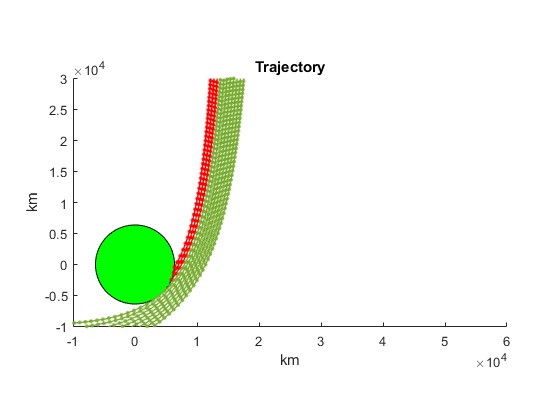

    
    xlabel("km")
    ylabel("km")
    title("Trajectory")
    axis equal
    axis([-10000 60000 -10000 30000])
    hold off

figure
clf
yyaxis right
plot(t_range / (365*24), impacts(2,:))
ylabel("Minimum Distance (km)")

yyaxis left
plot(t_range / (365*24), impacts, ".-", "Markersize", 20)
xlabel("Time of DART impact (years before potential earth impact)")
ylabel("Earth Impact")
ylim([-0.5 1.5])
yticks([0 1])

This shows that the 100 Teragram DART would have had to collide with the impactor at least 3 years in advance in order to deflect it enough as to not hit the earth.

## Interpretation

Theses initial results show that if we were able to launch a rocket that weighs 0.2 million times as much as the real DART spacecraft, we would only need to impact the Chicxulub asteroid three years in advance in order to redirect it safely away from earth.

In the next iteration of our model, we are considering adding a third body (the sun) as well as making some optimizations so that we can run our model with a realistic DART mass.